# Hands-On: C2D with Sampler & Hold - First Experiment

## First Scenario: Discretising  an LTI System with only Real Eigenvalues

Let's consider the continuous-time LTI system


$$\left\{ \begin{array}{lcl}
			\dot{x}(t) &=& \left[ \begin{array}{cc} 
												0 & 1\\0 & -1 
											\end{array} \right] \cdot x(t) + \left[\begin{array}{c} 0 \\ 10  \end{array} \right] \cdot u(t) \\[0.5em] \\
			y(t) &=&\left[ \begin{array}{cc}
									 1 & 0
									\end{array}  \right] \cdot x(t)
			\end{array} \right.$$


What happens, if you choose a few different sampling periods $\Delta_1\,,\; \Delta_2\,, \ldots \Delta_{10}$ such that

 
$$\Delta_i \in \left[ \frac{1}{1000} \,,\; 10 \right] \quad \forall i = 1\,,\;2\,, \ldots 10$$


and then compute the discrete-time description of the considered LTI system?

Write a piece of code, allowing:

-  To select a set of sample periods, as specified above;

-  To compute, for each selected sampling time, the discrete time representation of the given continuous time LTI system;

-  To plot the eigenvalues of the discrete-time description of the given LTI system;

- To compare the free state movement of the continuous time system and the free state movement of each discrete time description, starting from the initial state $x_{0} = \left[ \begin{array}{cc} -2 & +3 \end{array} \right]^{T}$


% write here the code solving the problem 

matA = [ 0 1; 0 -1 ];
matB = [ 0; 10 ];
matC = [ 1 0 ];
matD = 0;

% Deltas = linspace(1/1000,10,10);
Deltas = logspace(-3, 1, 10);

sysC = ss(matA,matB,matC,matD);
eig(sysC.A)

ans =      0
    -1


% impulse(sysC);

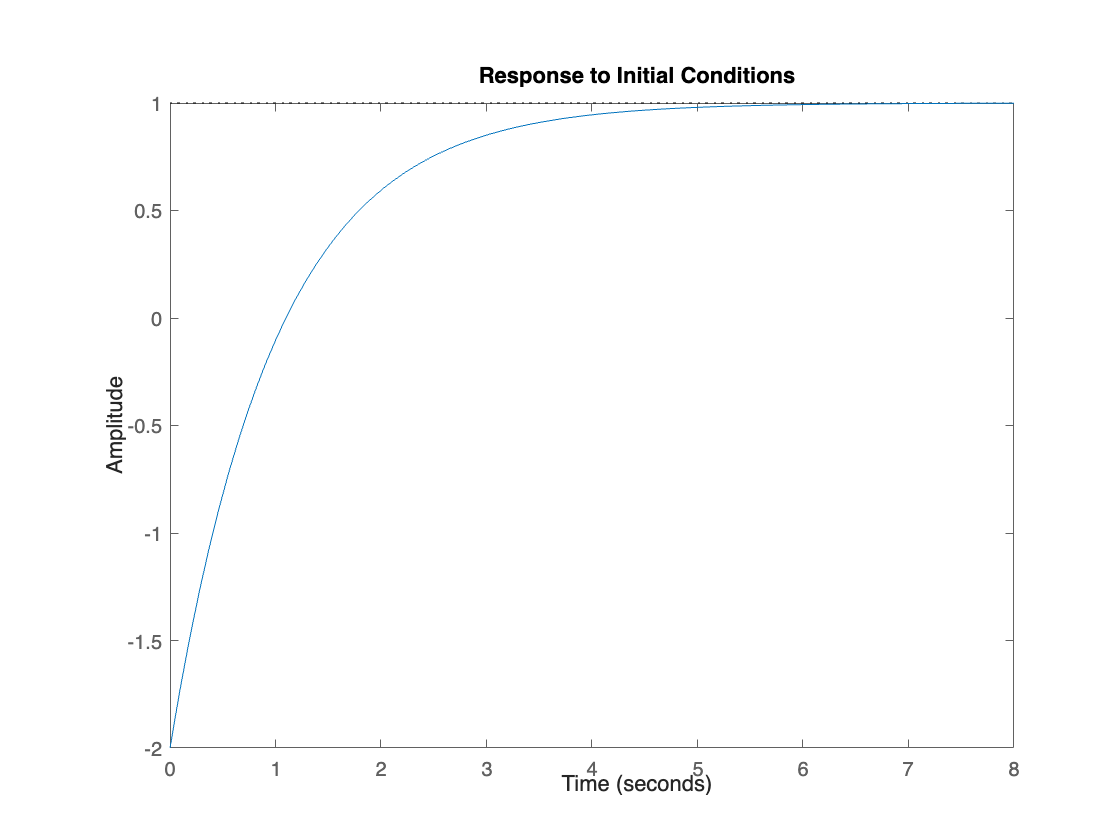

x_0 = [-2 3]';
initial(sysC,x_0);

whichOne = 1;
sysD = c2d(sysC,Deltas(whichOne)); % dipende dal tipo di campionamento che uso
    
% plot the eigenvalues of the discrete-time description of the given LTI system;

disp(eig(sysD.A)); % we use the matrix A to compare the eigen values corresponding to the free state moevement

    1.0000
    0.9990



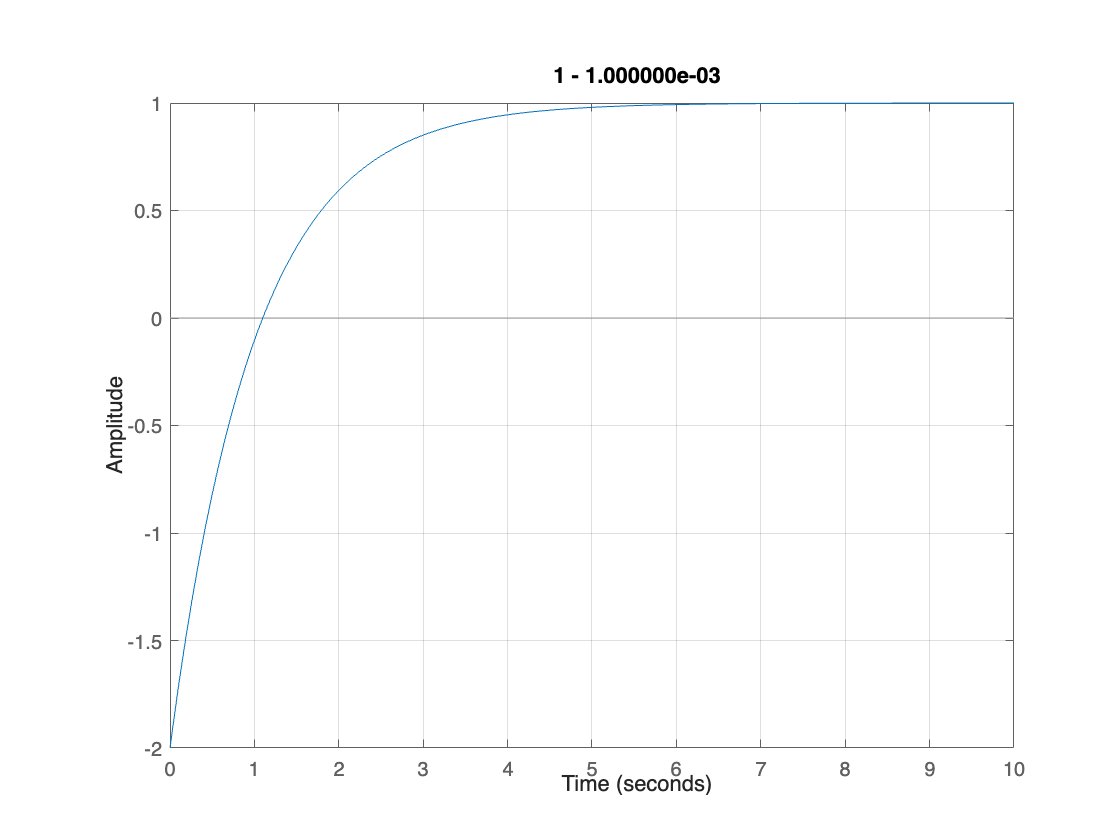


% compare the free state movement of the continuous time system and the free state movement of each discrete time description, starting from the initial state 

t = 0:Deltas(whichOne):10;
U = zeros(1, size(t, 2));
figure(whichOne);
lsim(sysD, U, t, x_0);
%[y_c, t_c] = initial(sysD, x_0);
%plot(t_c,y_c);
title(sprintf("%d - %s", whichOne, Deltas(whichOne)))
grid on;

    0.9990
    1.0000



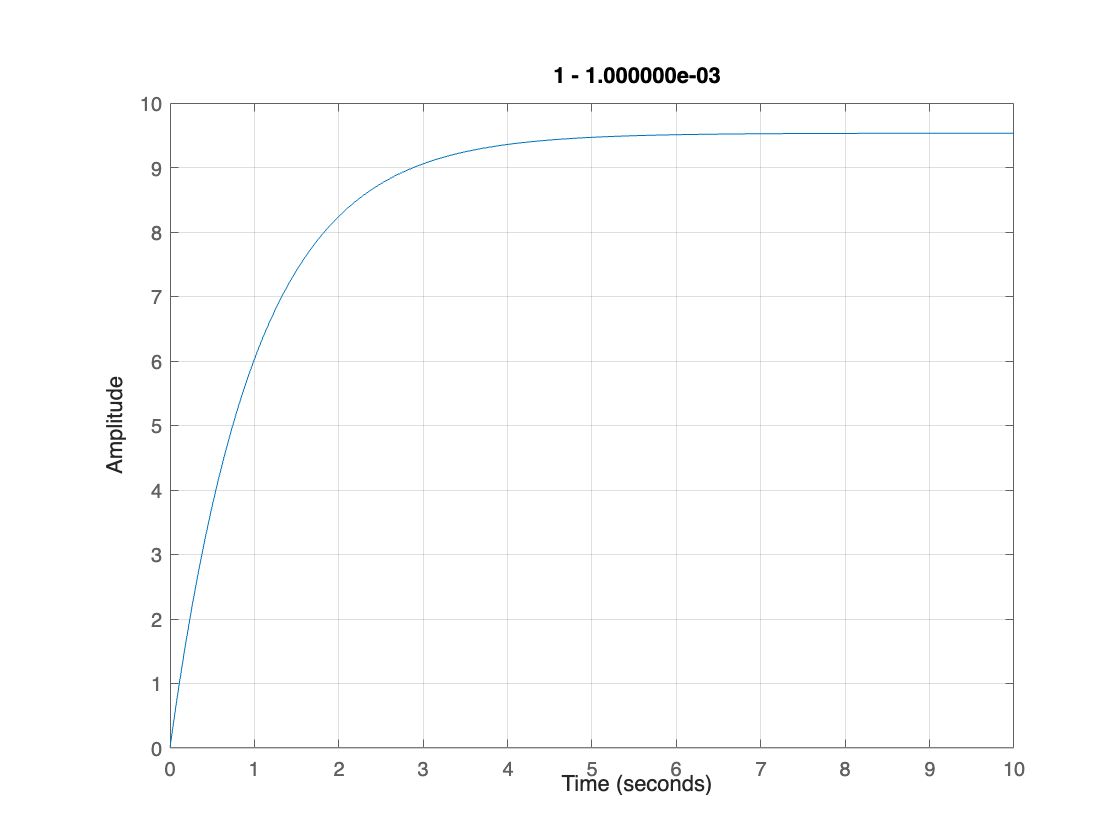

    0.9972
    1.0000



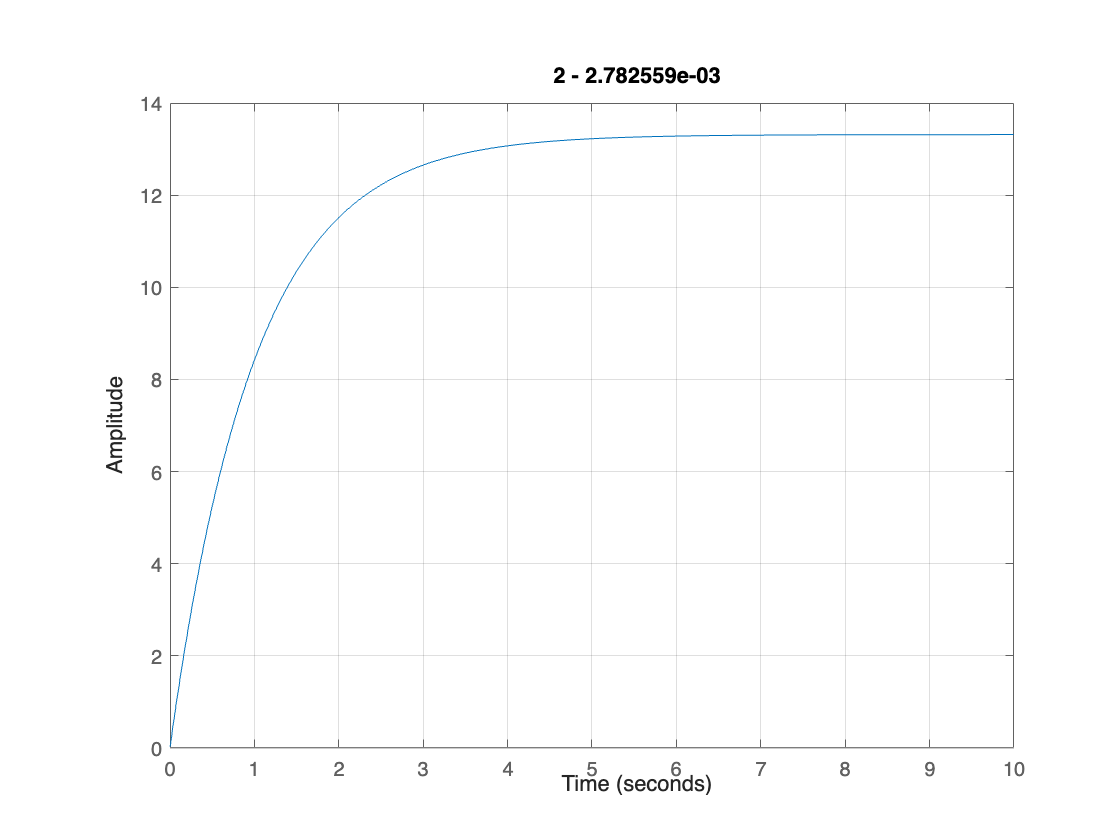

    0.9923
    1.0000



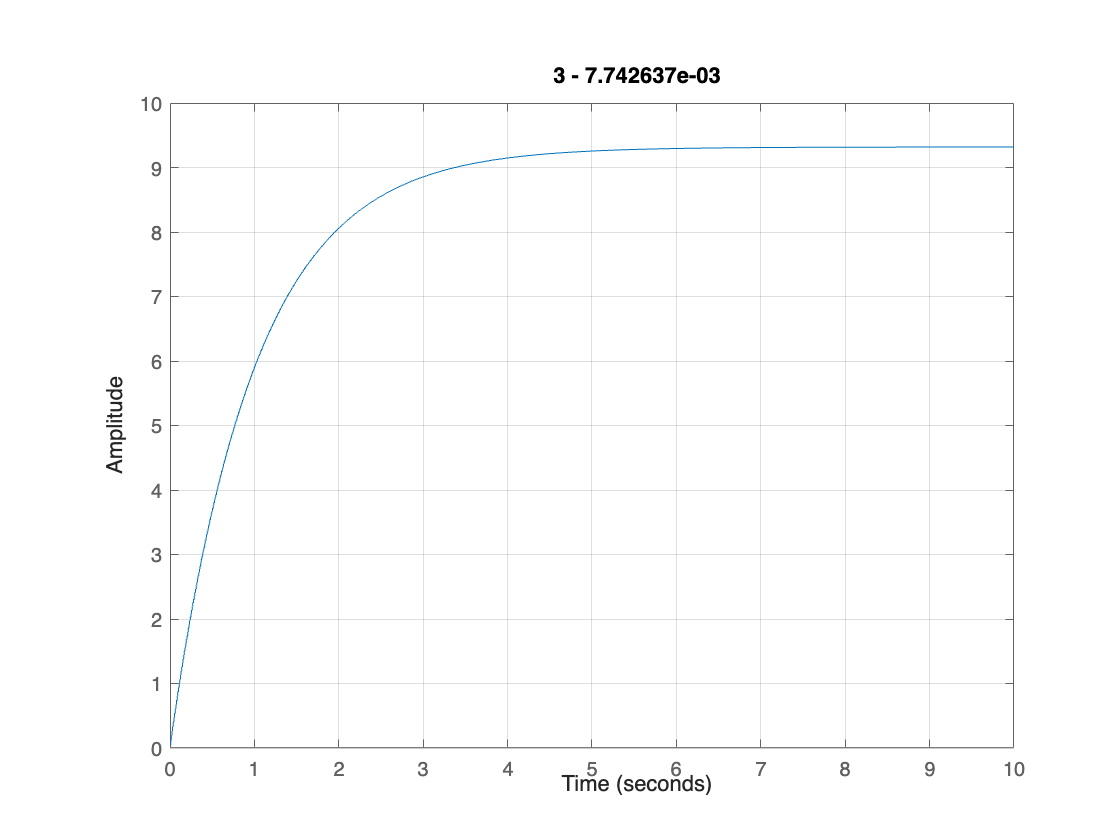

    0.9787
    1.0000



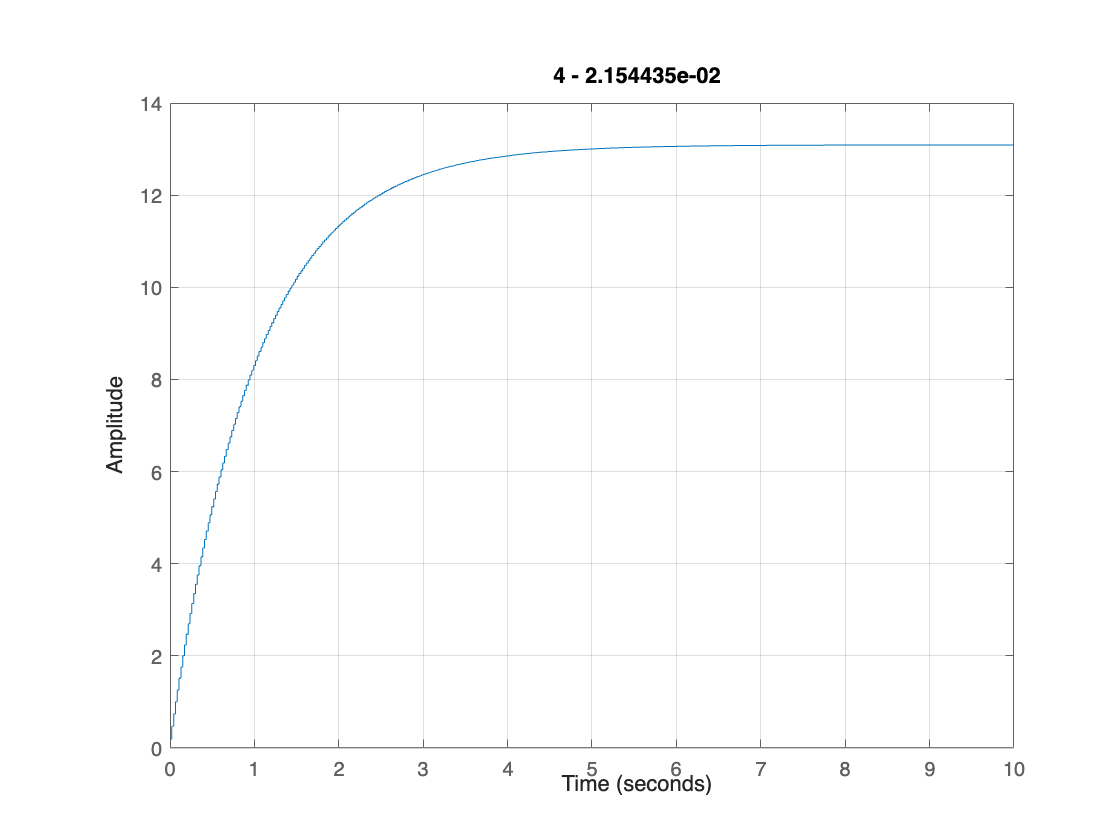

    0.9418
    1.0000



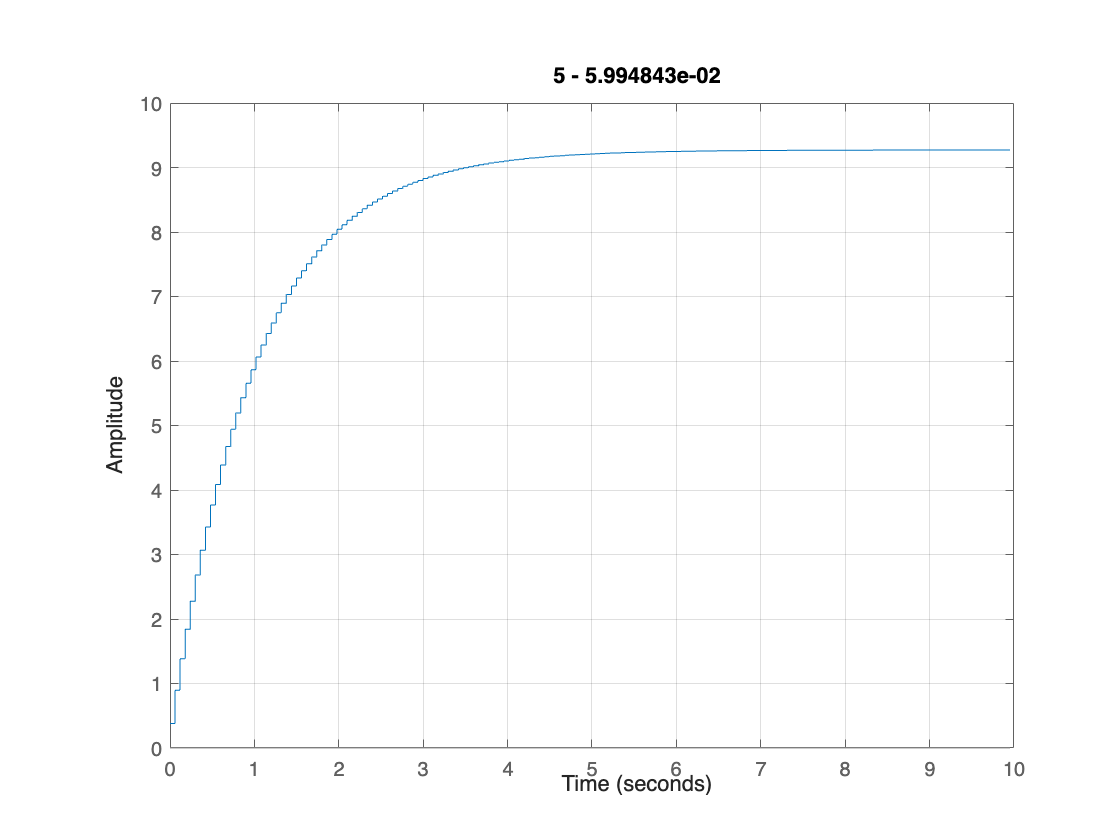

    0.8463
    1.0000



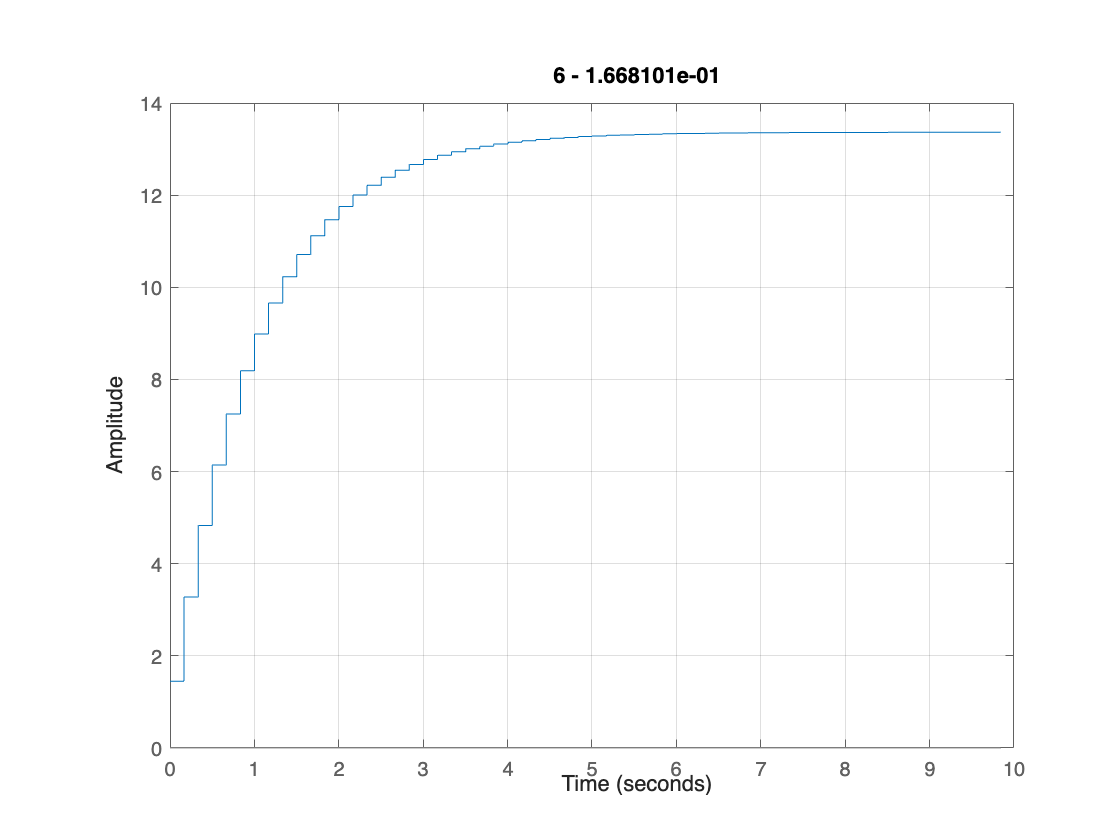

    0.6280
    1.0000



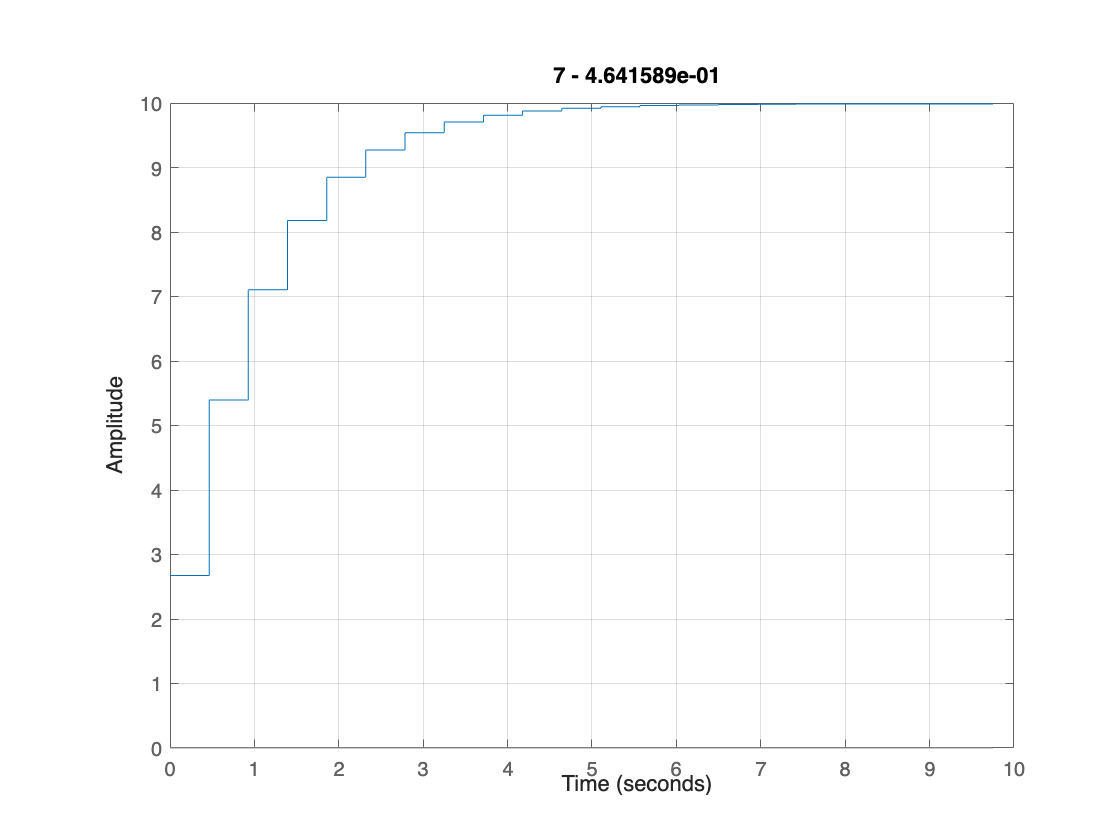

    0.2762
    1.0000



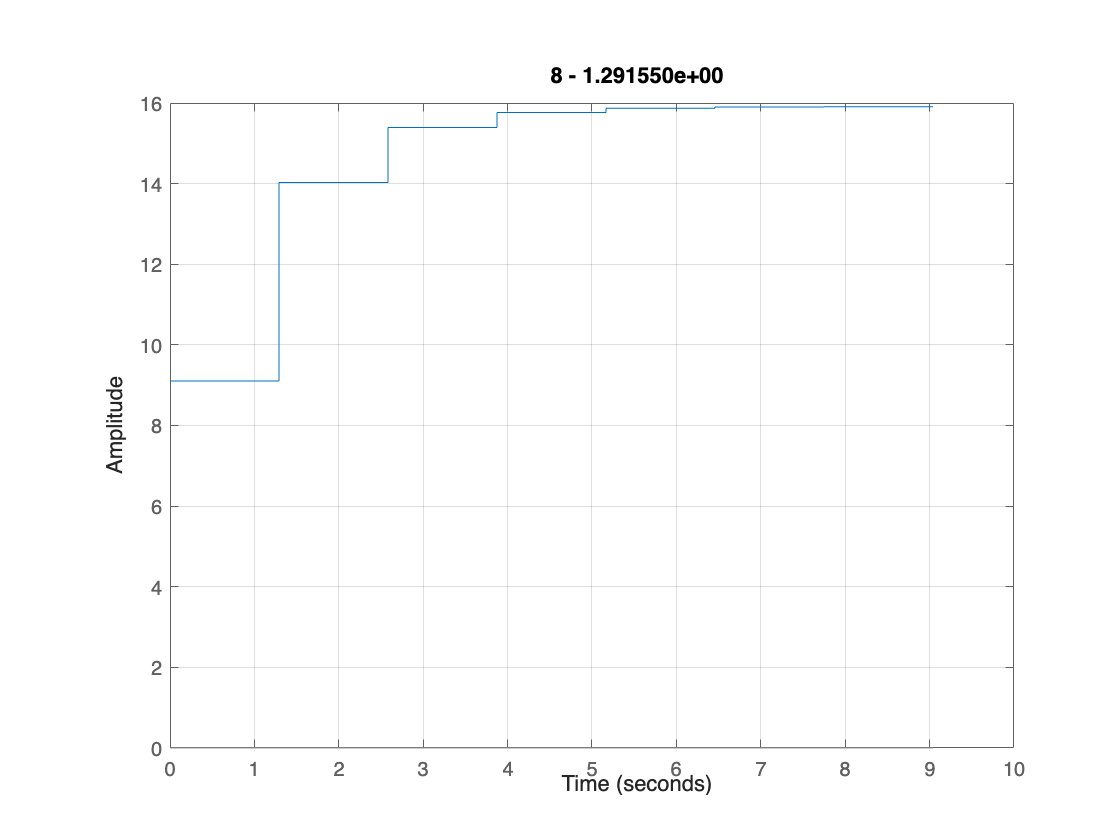

    1.0000
   -1.7147



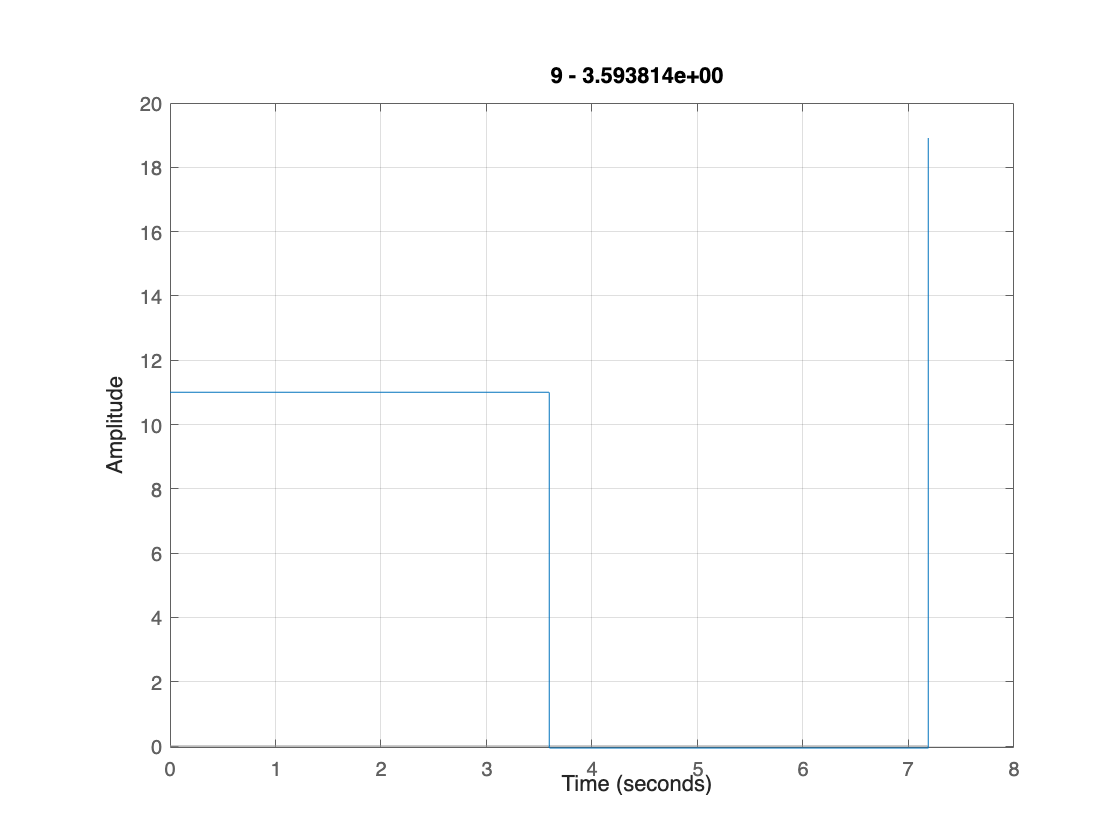

   -0.6307
    1.0000



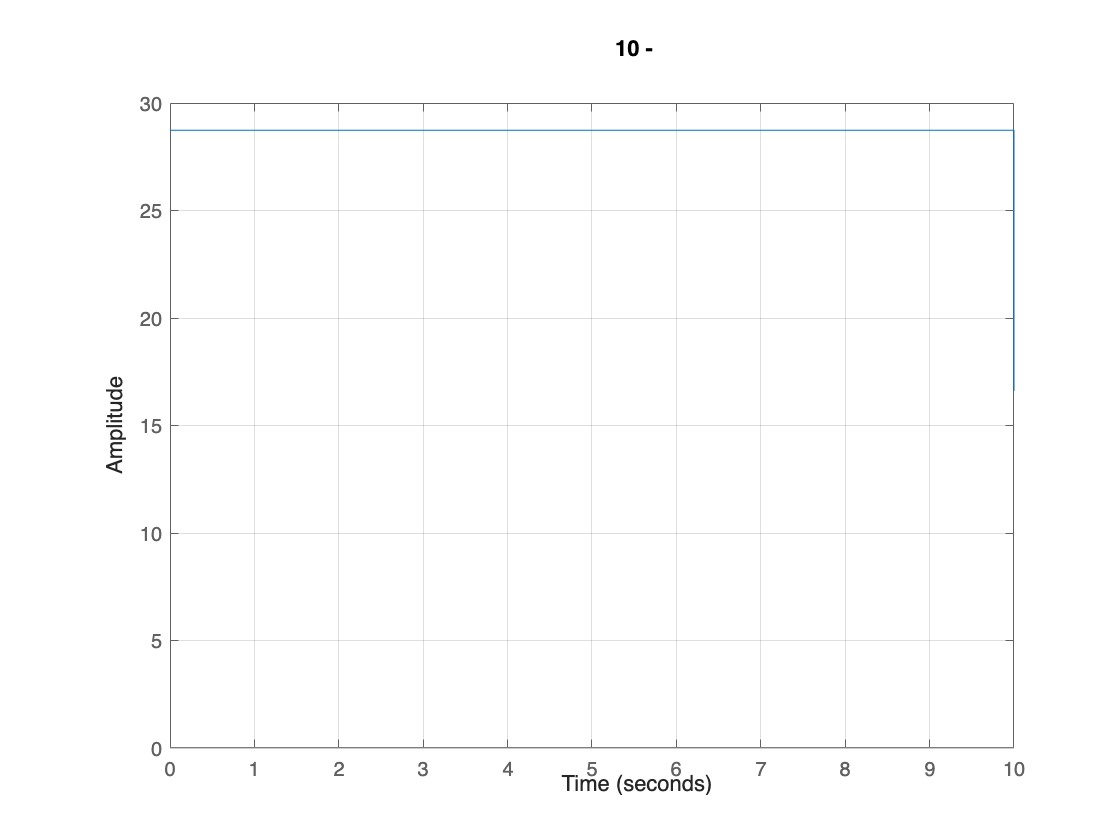

for whichOne = 1:size(Deltas, 2)
    sysD = c2d(sysC,Deltas(whichOne),"least squares"); % dipende dal tipo di campionamento che uso
    
    % plot the eigenvalues of the discrete-time description of the given LTI system;
    
    disp(eig(sysD.A)); % we use the matrix A to compare the eigen values corresponding to the free state moevement
    
    % compare the free state movement of the continuous time system and the free state movement of each discrete time description, starting from the initial state 
    x_0 = [-2 3]';
    
    t = 0:Deltas(whichOne):10;
    U = zeros(1, size(t, 2));
    figure(whichOne);
    lsim(sysD, U, t, x_0);
    title(sprintf("%d - %s", whichOne, Deltas(whichOne)))
    grid on;
end

- What could be the behavior of the discrete-time description eigenvalues, when increasing or decreasing the sampling frequency $f_s = 1/ \Delta$ ? 

The behavior of the discretized system was not easy to identify with the ZOH sampler because this one is a pretty ideal one, so all the output signals were looking like sampling of the original correct one and this may lead to wrong conclusions.

I chose to use another algorithm and with the "least-square" the beavior difference as the sample frequency is decreasing is clearer: the disctetized system is behaving less and less accurately (sometimes even in a totally wrong way) as the sample rate (thus the information stored by the model) decreases.

What's interesting to note is how the eigen values change:

- in the original continous system the two eigen values are $[0, -1]$, which means that the system is stable as per hypothesis.

- As we discretize it, in the first scenario (where we have the highest sample frequency, so the best scenario that we will look at), we see that the eigenvalues already change to $[0.999, 1]$ .

- We don't have to confuse the meaning of the eigenvalues in the two cases: while on a continuous-time model, having an eigen value $\geq 1$ is a symptom of instability (because one of the solution will look like $y(t) = e^{\lambda t}$, thus for $t \rightarrow \inf$, we would get $y \rightarrow \inf$), in a discrete model (for example in the first discretization, where in the chart we can see that our approximation is good enough, eigen values are $[0.999, 1]$) having them greater than zero would mean that the solution of $x(k)=A^kx(0)$ is stable as long as $A \leq 1$.

- As the sampling frequency decreases (thus more and more information is being discarded), we can notice how one eigen value is converging towards zero (if we are using the ZOH), while if we are using the least-square algorithm, we can notice that the response of the system is simply not consistent with the continous-time model

- Did you find any difference between the free movement of the state of the original continuous-time system and the discrete-time representations you obtained?

As we reduce the sampling rate, the outcome is less and less precise. In particular if we have a look from the $0.168 Hz$ and lower sampling frequencies, we can notice that in some cases it's still possible to determine the general trend of the movement, but the starting point (if we take the least-squares into consideration) is no more $-2
$, which may lead to wrong analysys.

- Finally, analysing the results, try to figure out a good choice for $\Omega_{\text{B}}$, or equivalently for $f_{\text{B}}$ , in order to obtain a proficient discrete-time description of the given LTI system.

The minimum samping frequency is $5.99e-2$, since the first sampled point is close enough to the origin.

## Now suppose to feed the continuous time system with the input 


$$u(t) = t e^{-4t}\sin \left(2 \pi \bar{f}t - \frac{pi}{6}\right)\cdot 1(t) \quad \bar{f} = 2.0\;\text{[Hz]}$$


and assume to sample also the input signal, beside the state and the output variables.


% write here the code solving the problem 

f = 200;

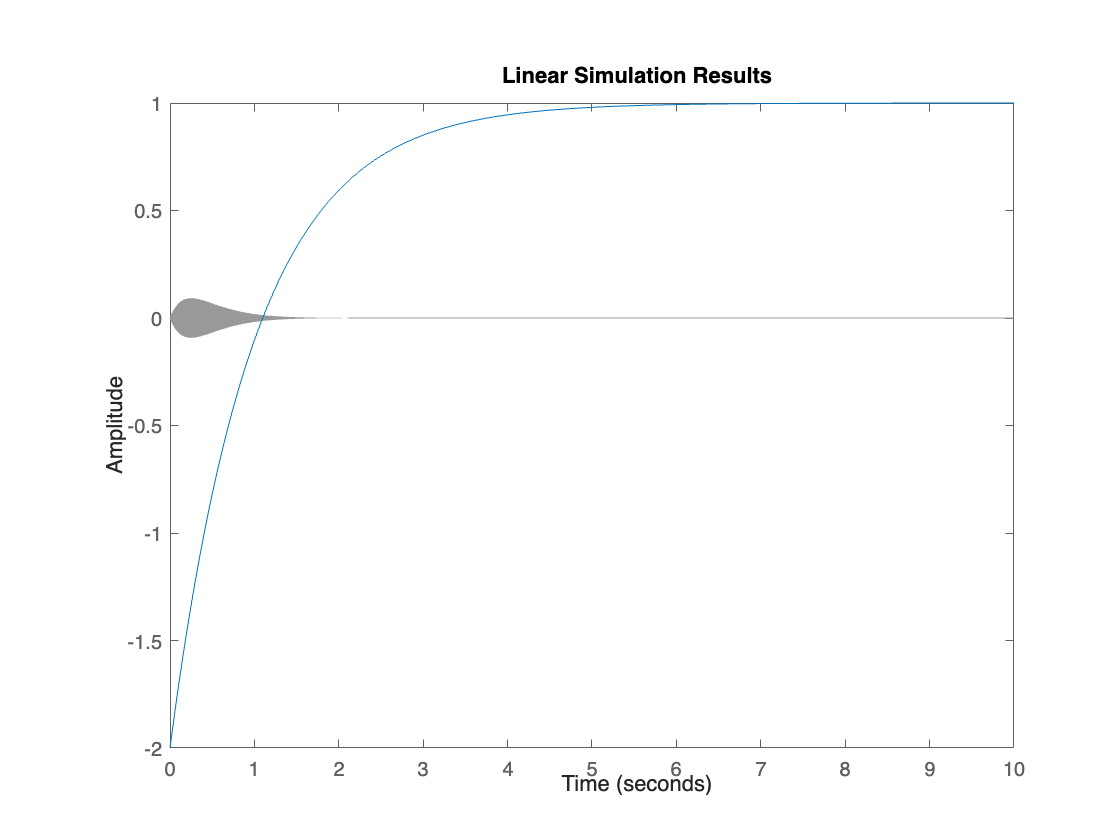

t = 0:0.0001:10;
x_0 = [-2 3]';
U = t.*exp(-4*t) .* sin(2*pi*f*t - pi/6) .* heaviside(t);
lsim(sysC, U, t, x_0)

for j = 1:size(Deltas,2)
    disp(eig(sysD.A)); % we use the matrix A to compare the eigen values corresponding to the free state moevement
end

   -0.6307
    1.0000

   -0.6307
    1.0000

   -0.6307
    1.0000

   -0.6307
    1.0000

   -0.6307
    1.0000

   -0.6307
    1.0000

   -0.6307
    1.0000

   -0.6307
    1.0000

   -0.6307
    1.0000

   -0.6307
    1.0000



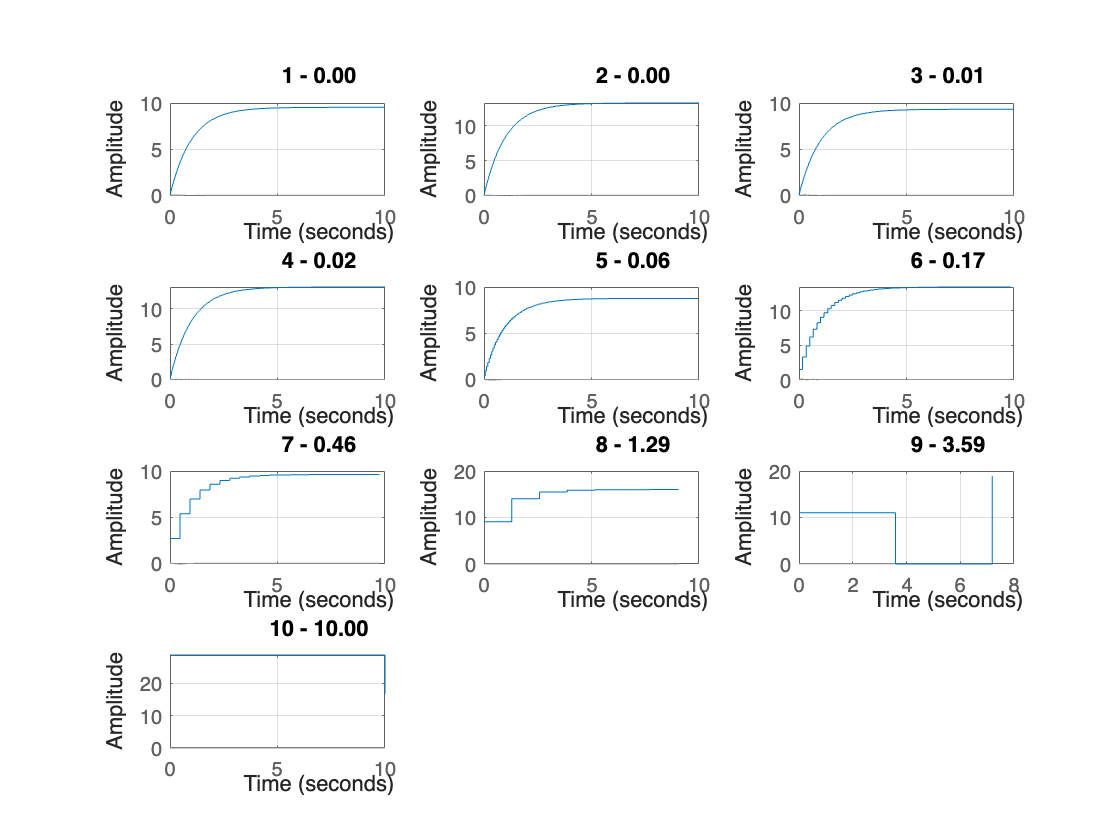


for whichOne = 1:size(Deltas, 2)
    sysD = c2d(sysC,Deltas(whichOne), "least-squares");
    
    % plot the eigenvalues of the discrete-time description of the given LTI system    
    t = 0:Deltas(whichOne):10;
    U = t.*exp(-4*t) .* sin(2*pi*f*t - pi/6) .* heaviside(t);

    subplot(4,3,whichOne);
    lsim(sysD, U, t, x_0);
    hold on;
    % plot the state movement

    title(sprintf("%d - %.2f", whichOne, Deltas(whichOne)))
    grid on;
    hold off;
end

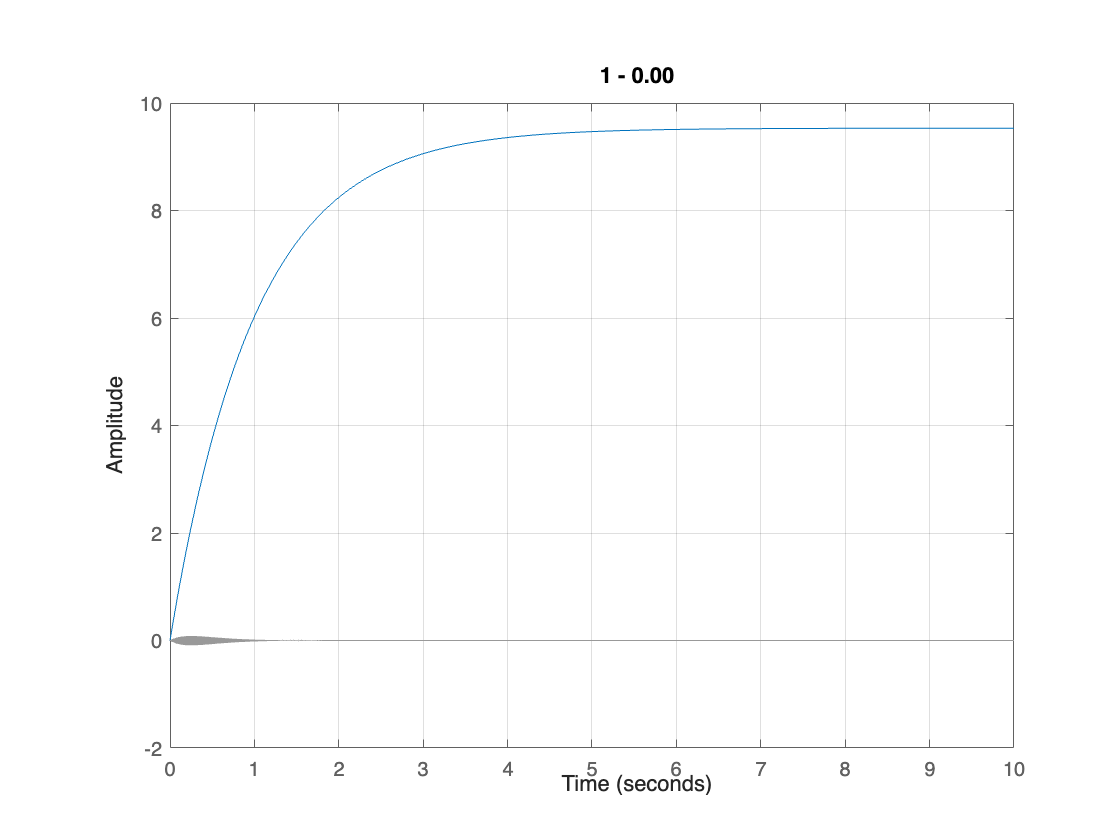

whichOne = 1;
sysD = c2d(sysC,Deltas(whichOne), "least-squares");
    
% plot the eigenvalues of the discrete-time description of the given LTI system    
t = 0:Deltas(whichOne):10;
U = t.*exp(-4*t) .* sin(2*pi*f*t - pi/6) .* heaviside(t);

figure(1);
lsim(sysD, U, t, x_0);
hold on;
% plot the state movement

title(sprintf("%d - %.2f", whichOne, Deltas(whichOne)))
grid on;
hold off;

sysD.StatePath

ans = 2×1 cell array
    {0×0 char}
    {0×0 char}


- Is the previously chosen sampling period still a good choice? Or do you have to select a different value?

Yes, the choice is still good because the reconstructed system is behaving pretty closely to the continuous.

- What if $\bar{f} = 200.0 \; \text{[Hz]}$?

No significan behavior difference was noticed. **CHECK THIS!!!!!!**

- Write a few lines of code, implementing a comparison of the state and output movements, starting from the assigned initial state $x_0$ and the predefined input, for the continuous-time system and the discrete-time representation obtained, discretizing the system equations according to the chosen sampling period.

% state and output

## Second Scenario: Discretising an LTI System with Complex Eigenvalues

Consider now the continuous-time LTI system


$$\left\{ \begin{array}{lcl}
			\dot{x}(t) &=& \left[ \begin{array}{cc} 
												1 & 2\\-2 & 1 
											\end{array} \right] \cdot x(t) + \left[\begin{array}{c} 0 \\ 10  \end{array} \right] \cdot u(t) \\[0.5em] \\
			y(t) &=&\left[ \begin{array}{cc}
									 1 & 0
									\end{array}  \right] \cdot x(t)
			\end{array} \right.$$


and repeat the same computation steps. What is your finding?


% write here the code solving the problem 

matA = [ 1 2; -2 1 ];
matB = [ 0; 10 ];
matC = [ 1 0 ];
matD = 0;

Deltas = logspace(-3, 1, 10);

sysC = ss(matA,matB,matC,matD);

eig(sysC)

ans =    1.0000 + 2.0000i
   1.0000 - 2.0000i


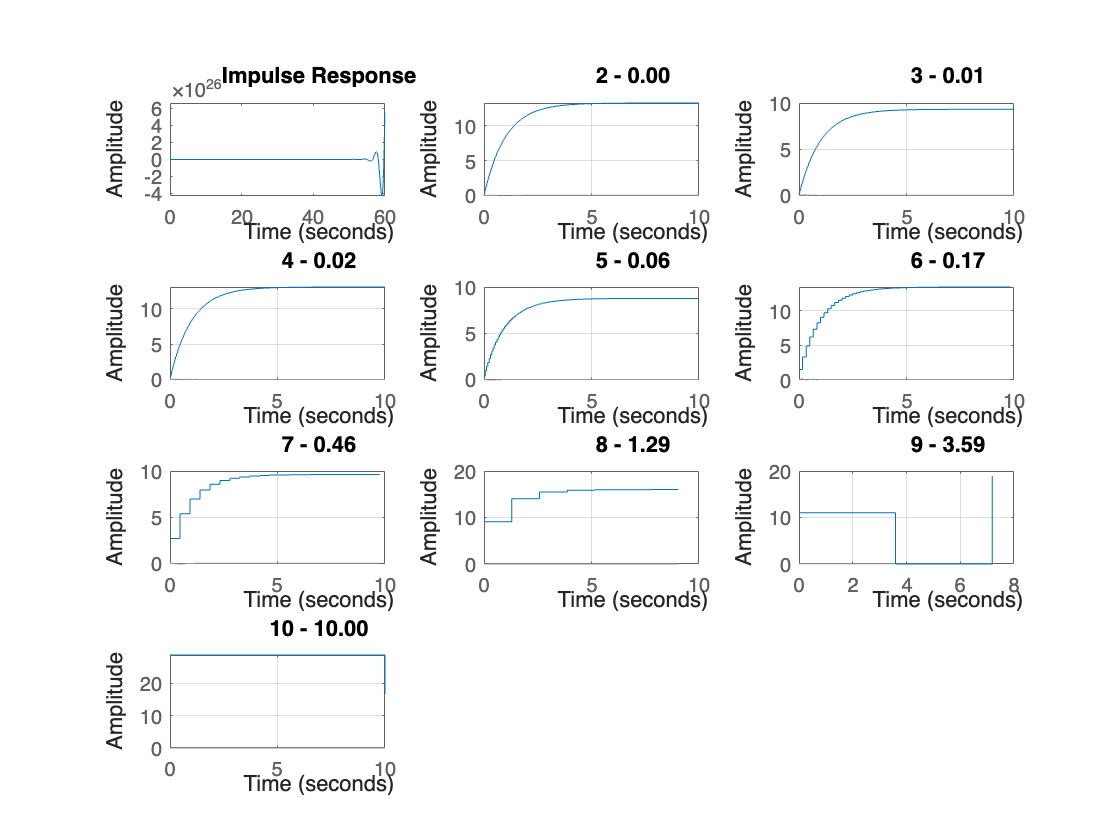

impulse(sysC);

   1.0010 + 0.0020i
   1.0010 - 0.0020i



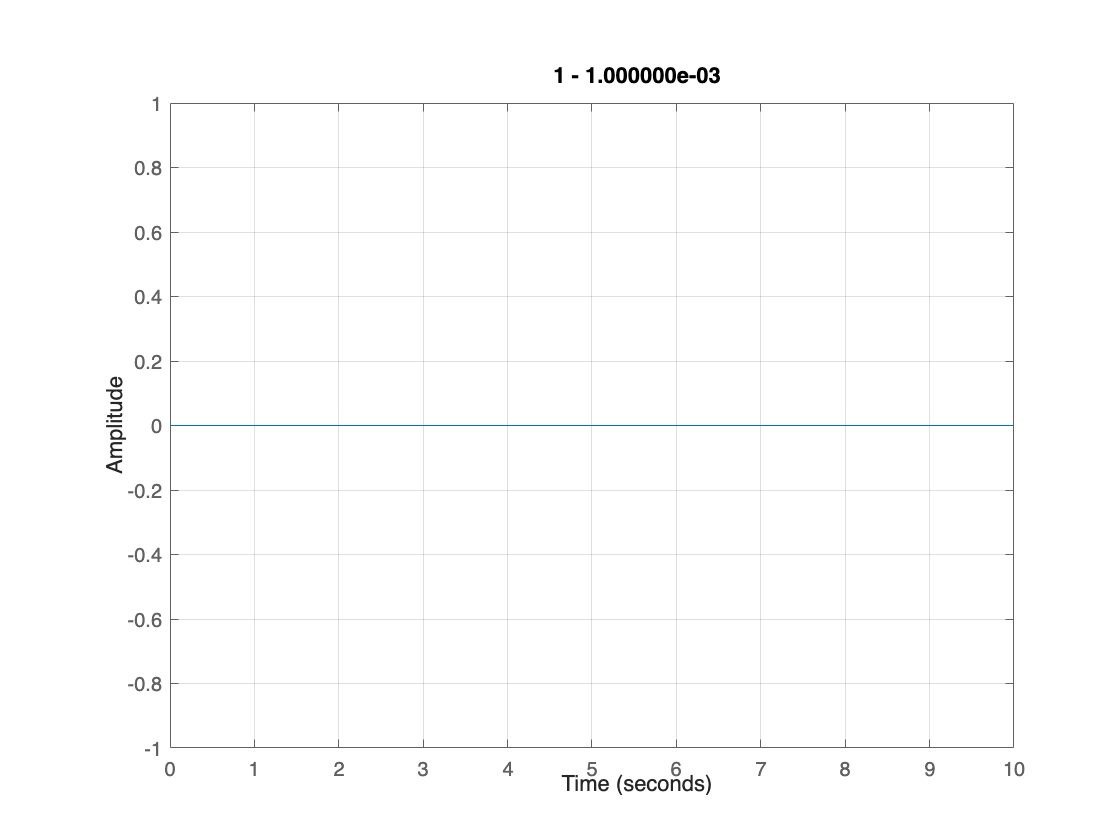

   1.0028 + 0.0056i
   1.0028 - 0.0056i



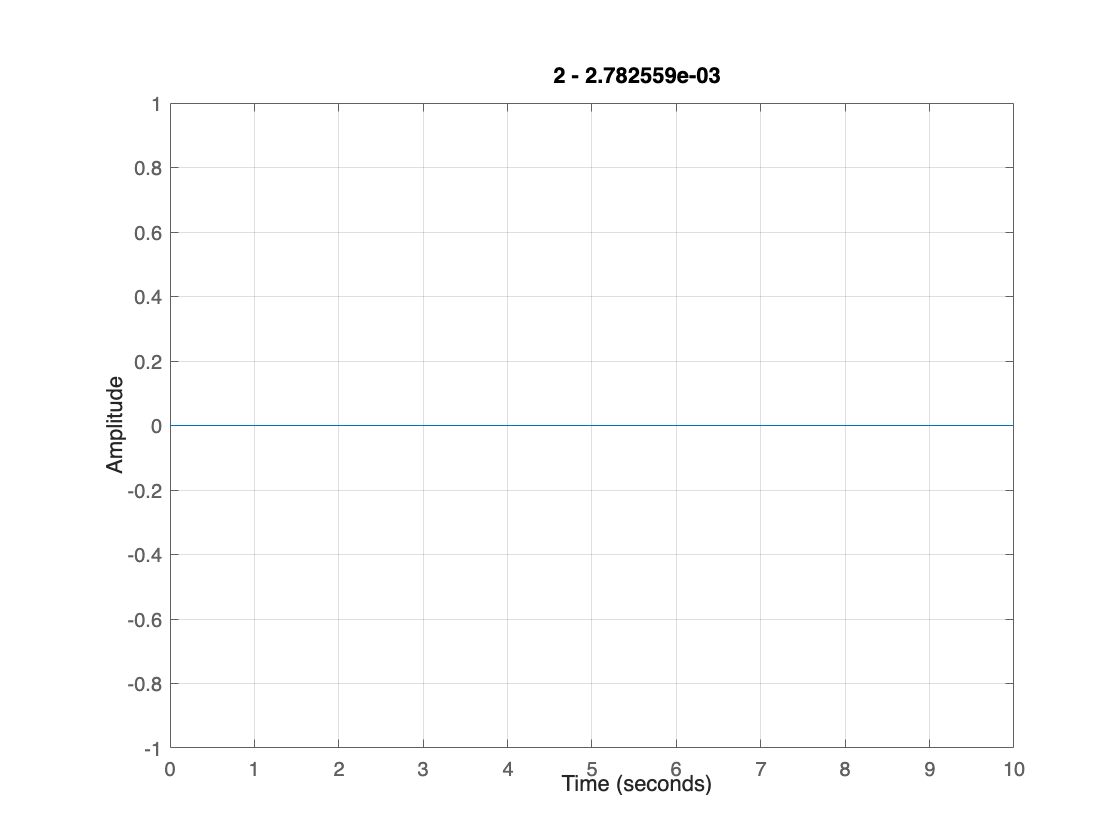

   1.0077 + 0.0156i
   1.0077 - 0.0156i



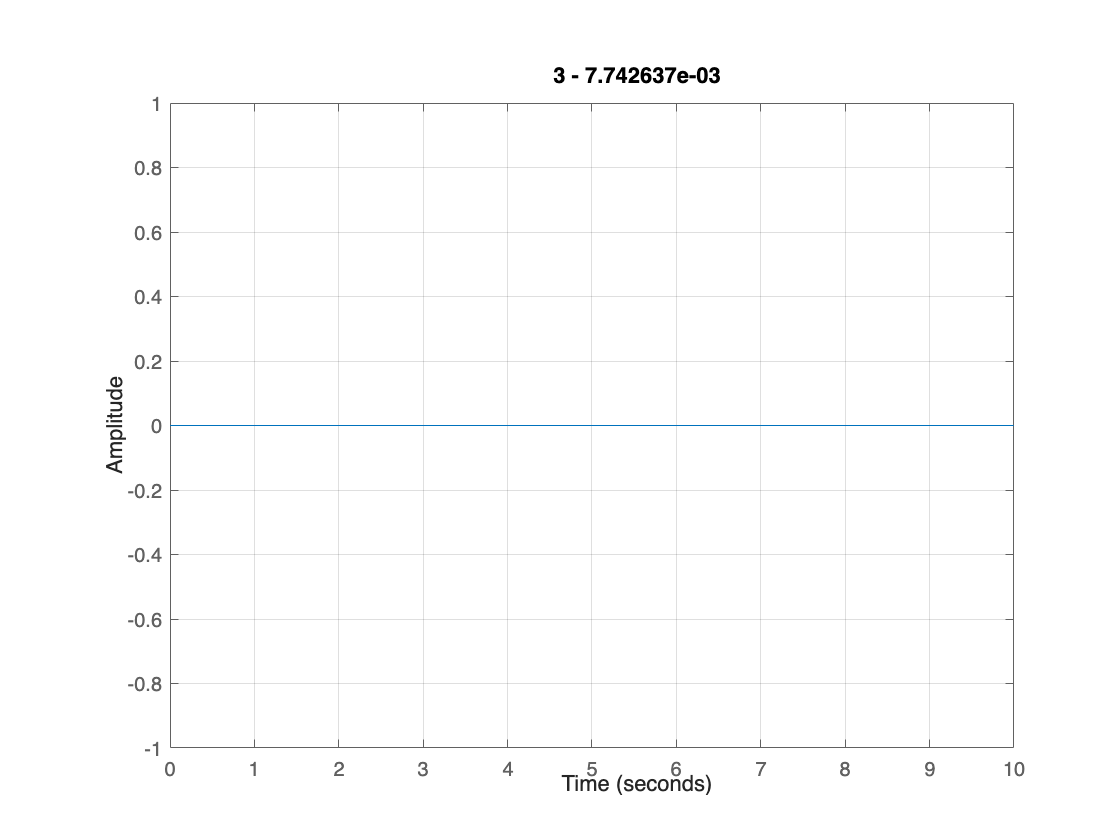

   1.0208 + 0.0440i
   1.0208 - 0.0440i



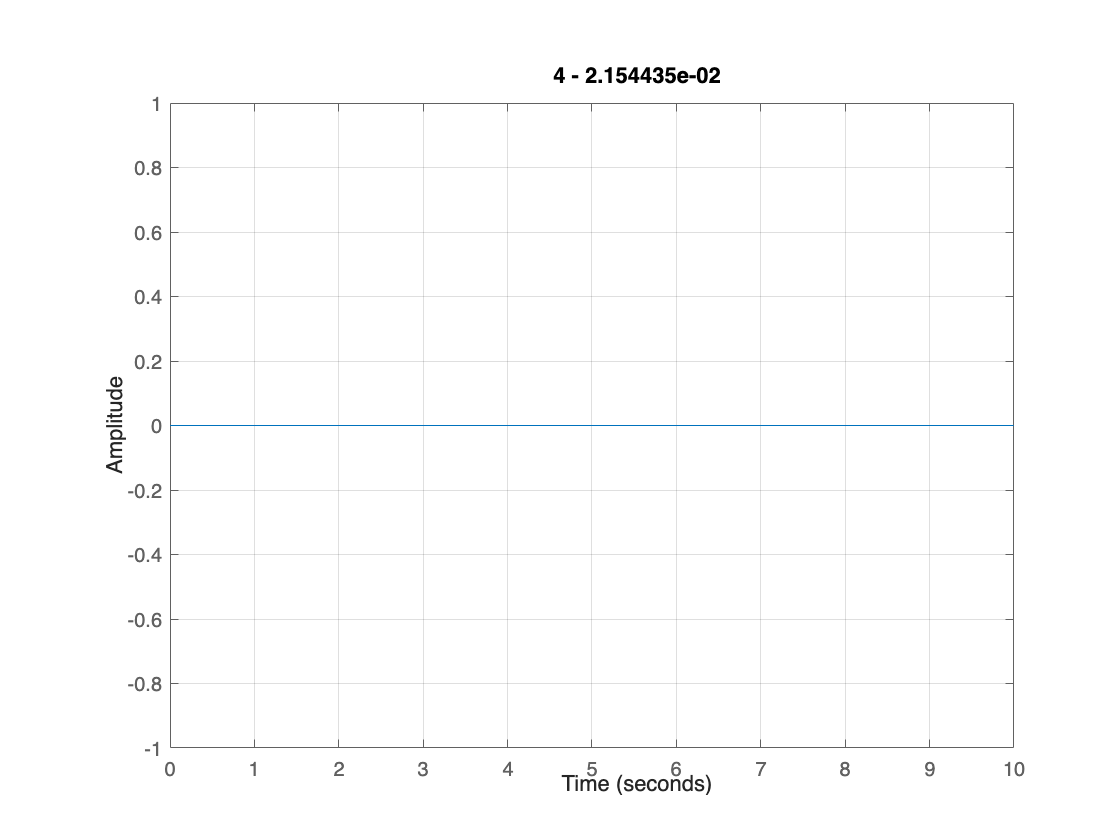

   1.0542 + 0.1270i
   1.0542 - 0.1270i



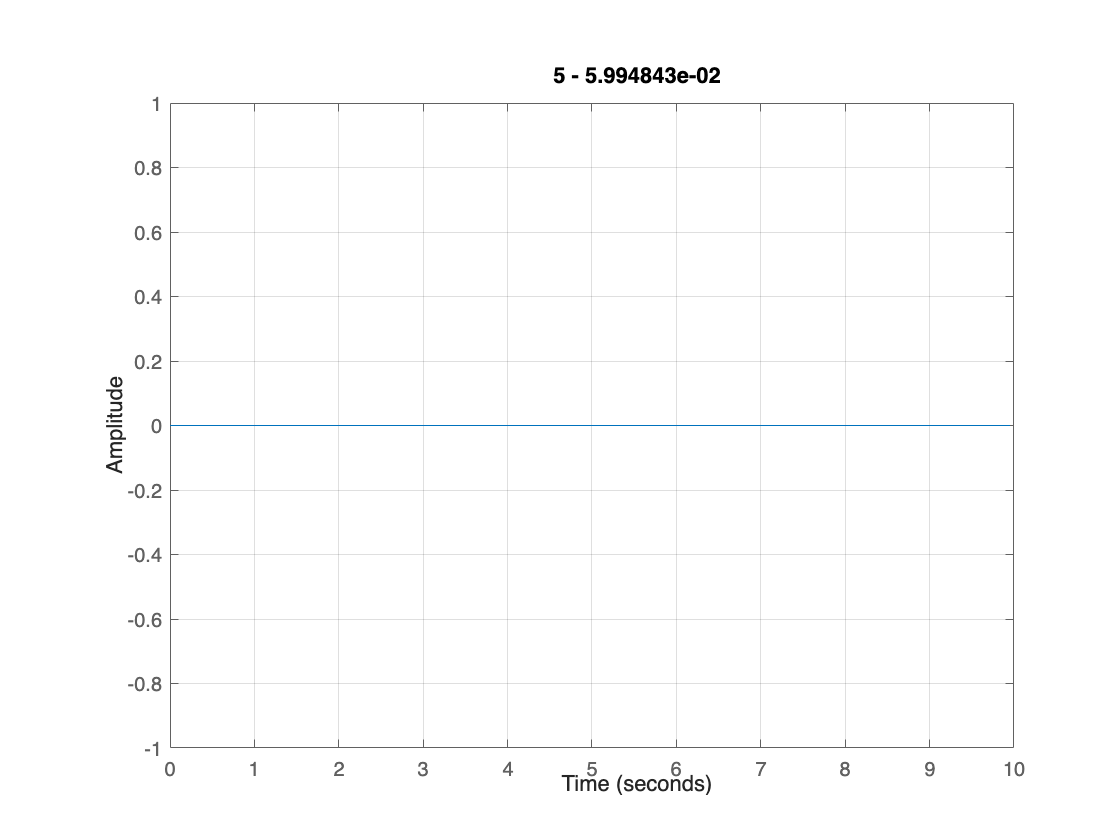

   1.1164 + 0.3869i
   1.1164 - 0.3869i



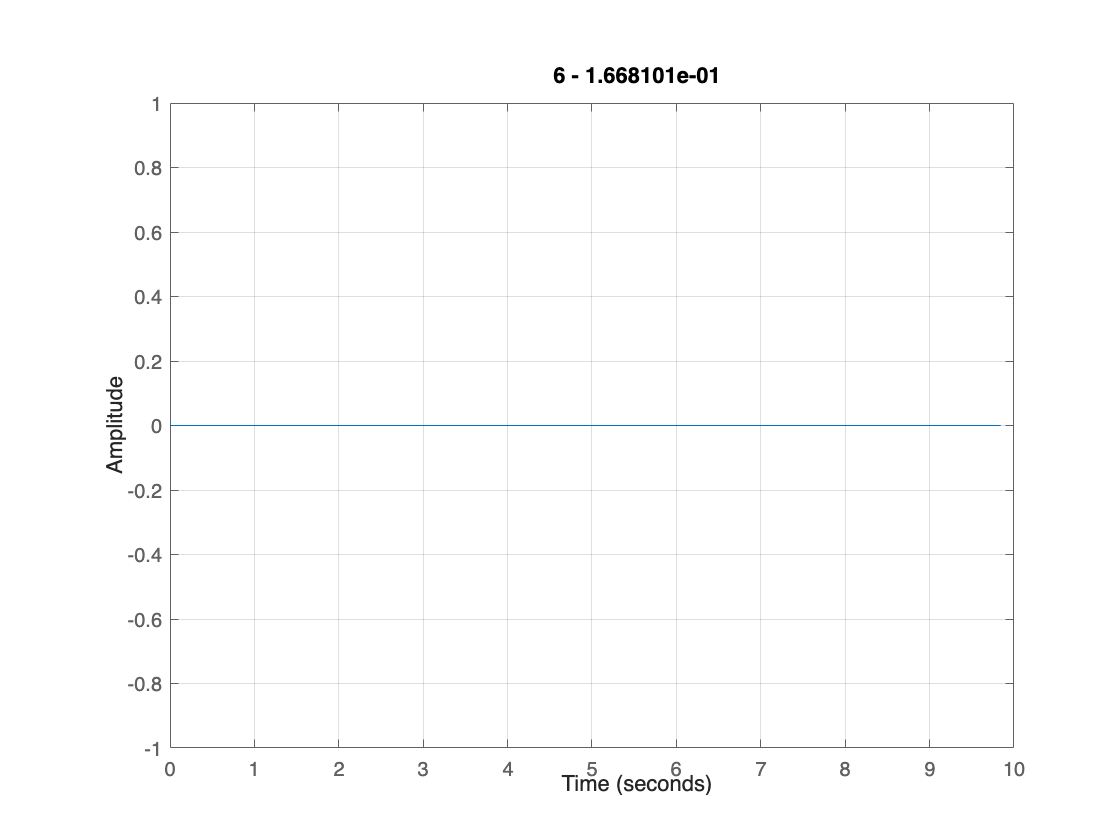

   0.9531 + 1.2735i
   0.9531 - 1.2735i



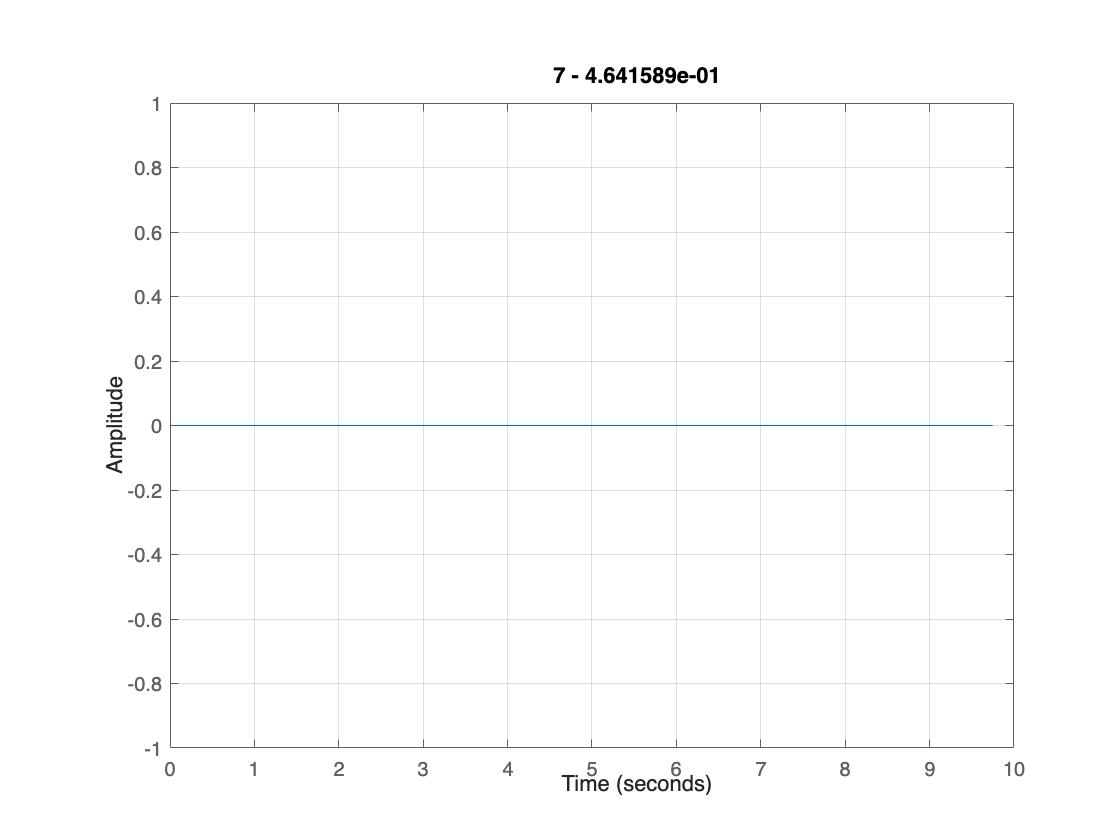

  -3.0856 + 1.9280i
  -3.0856 - 1.9280i



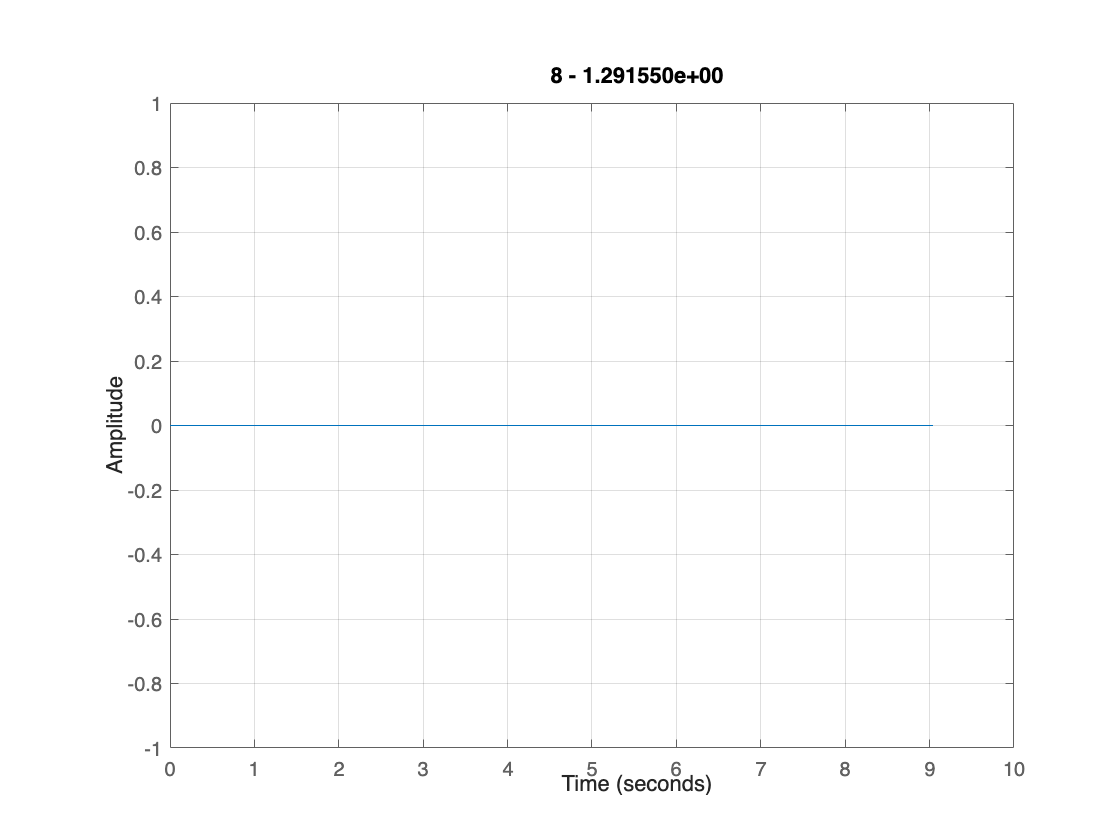

  22.4827 +28.5917i
  22.4827 -28.5917i



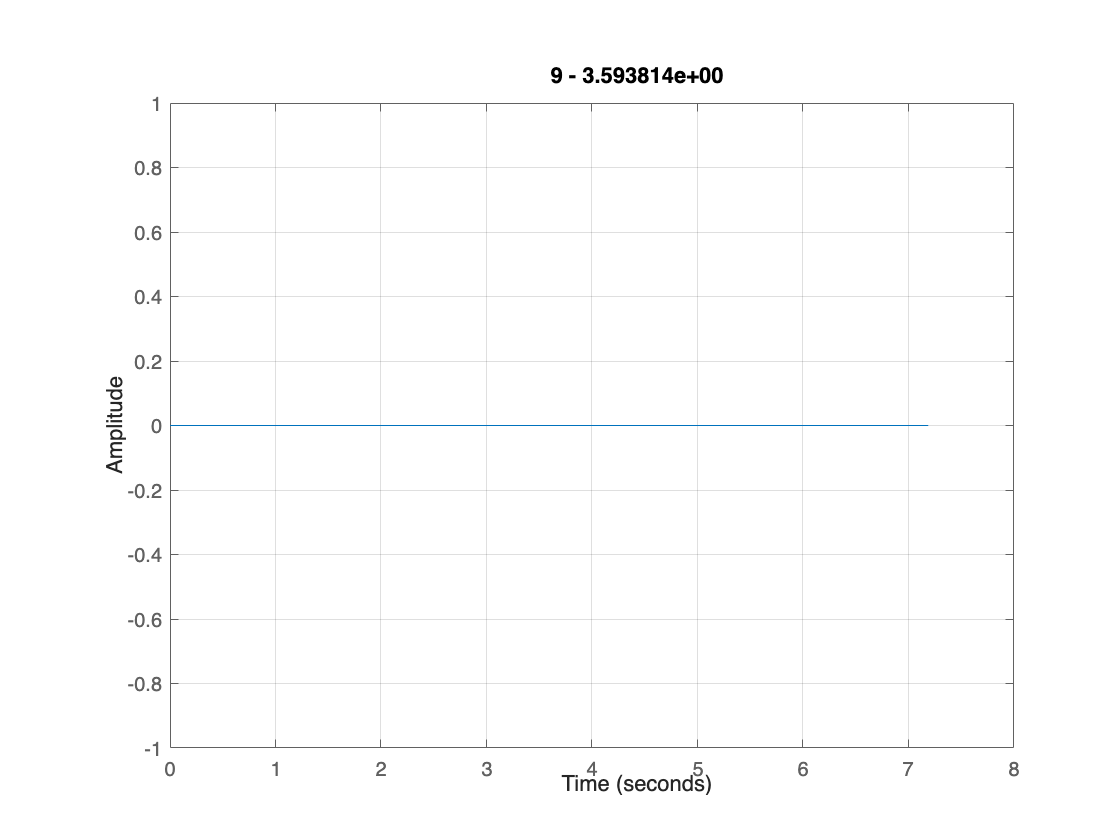

   1.0e+04 *

   0.8989 + 2.0109i
   0.8989 - 2.0109i



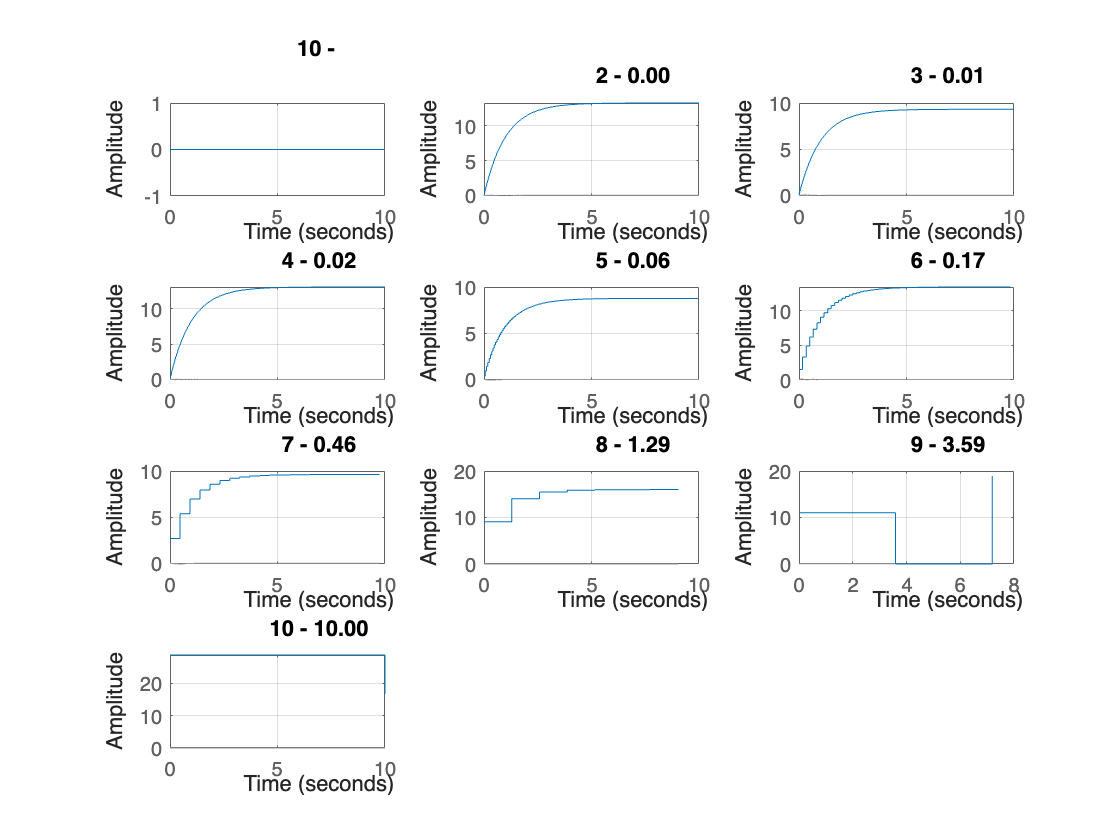

for whichOne = 1:size(Deltas, 2)
    sysD = c2d(sysC,Deltas(whichOne));
    
    % plot the eigenvalues of the discrete-time description of the given LTI system;
    
    disp(eig(sysD.A)); % we use the matrix A to compare the eigen values corresponding to the free state moevement
    
    % compare the free state movement of the continuous time system and the free state movement of each discrete time description, starting from the initial state 
    x_0 = [0 0]';
    
    t = 0:Deltas(whichOne):10;
    U = zeros(1, size(t, 2));
    figure(whichOne);
    lsim(sysD, U, t, x_0);
    title(sprintf("%d - %s", whichOne, Deltas(whichOne)))
    grid on;
end

SECOND CASE!!!

f = 200;

   1.0010 + 0.0020i
   1.0010 - 0.0020i



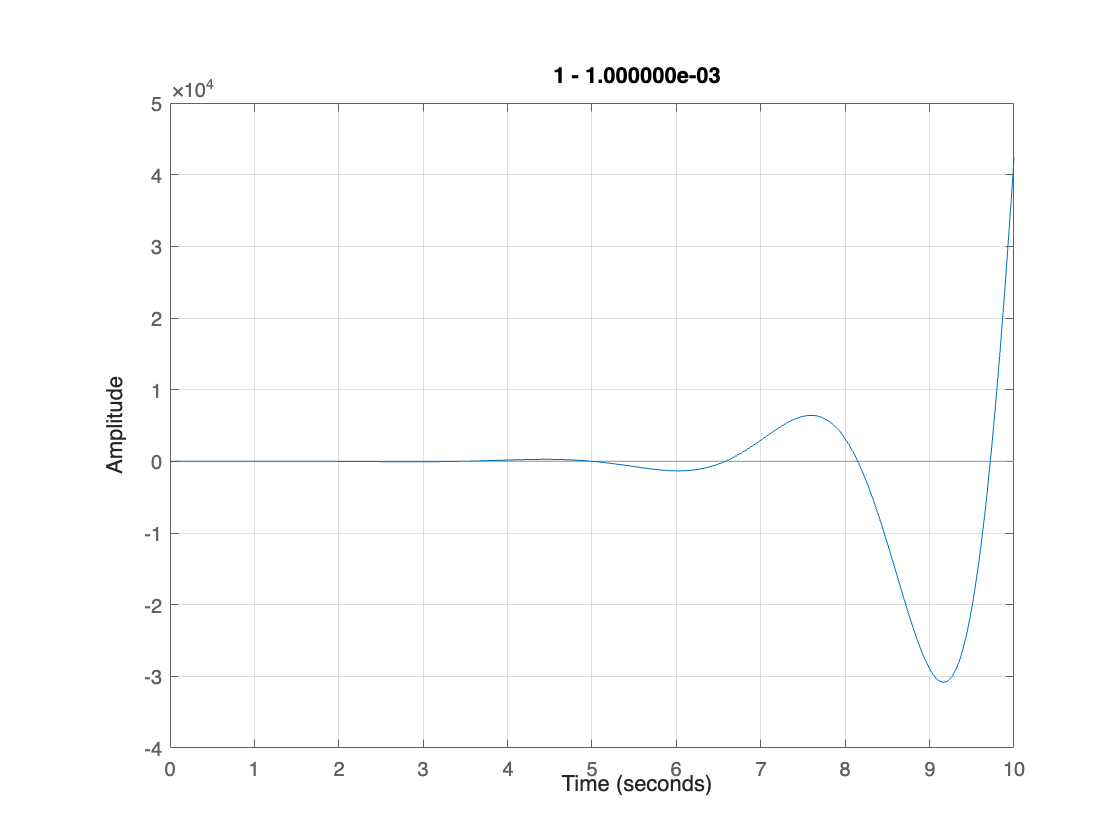

   1.0028 + 0.0056i
   1.0028 - 0.0056i



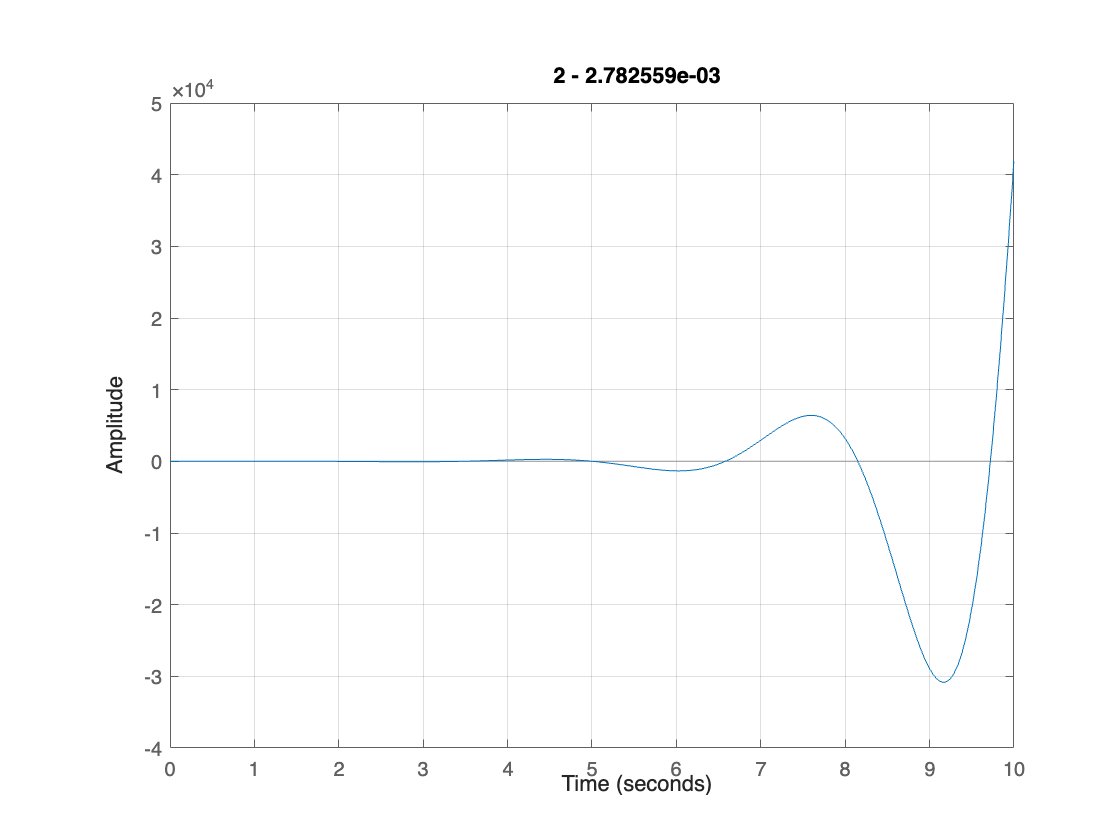

   1.0077 + 0.0156i
   1.0077 - 0.0156i



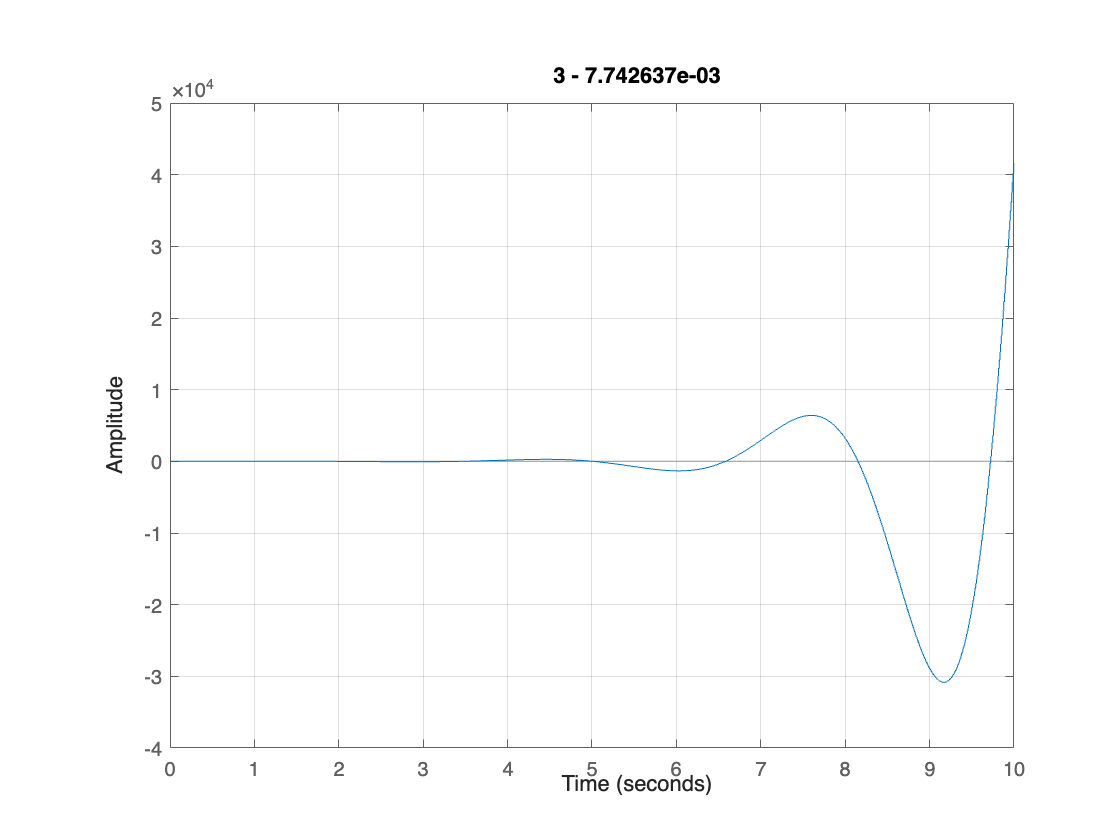

   1.0208 + 0.0440i
   1.0208 - 0.0440i



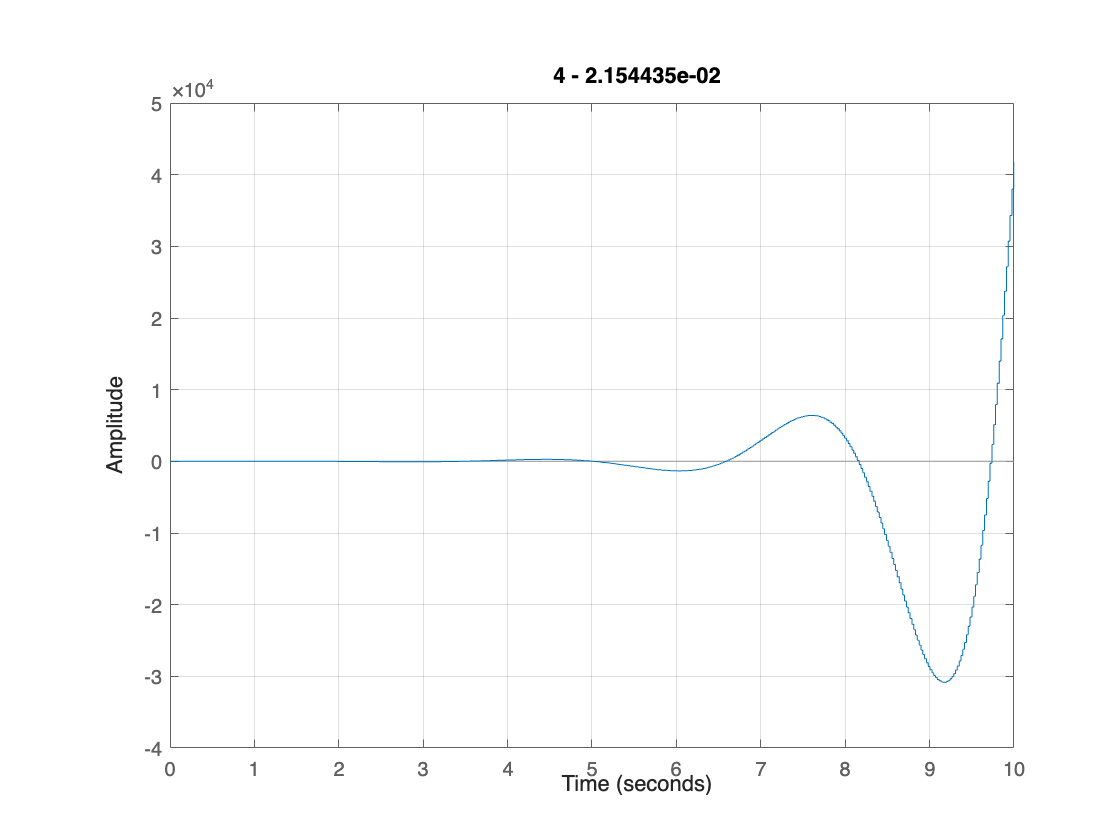

   1.0542 + 0.1270i
   1.0542 - 0.1270i



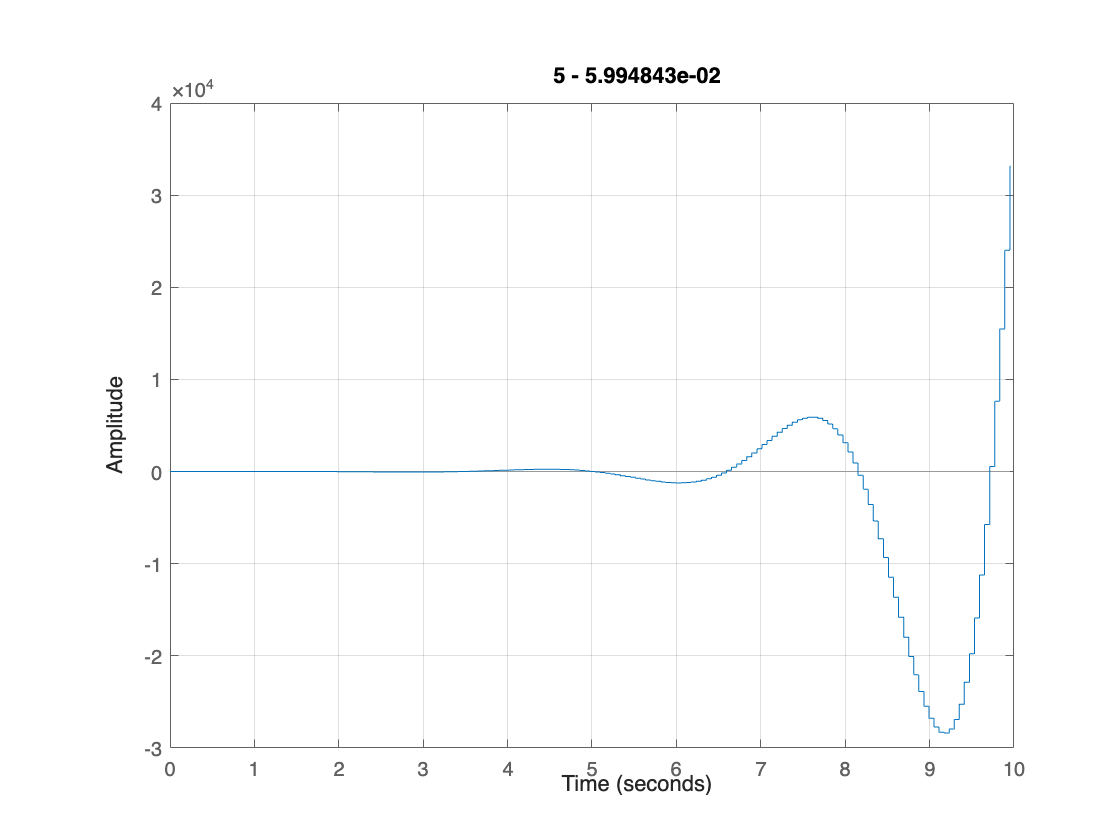

   1.1164 + 0.3869i
   1.1164 - 0.3869i



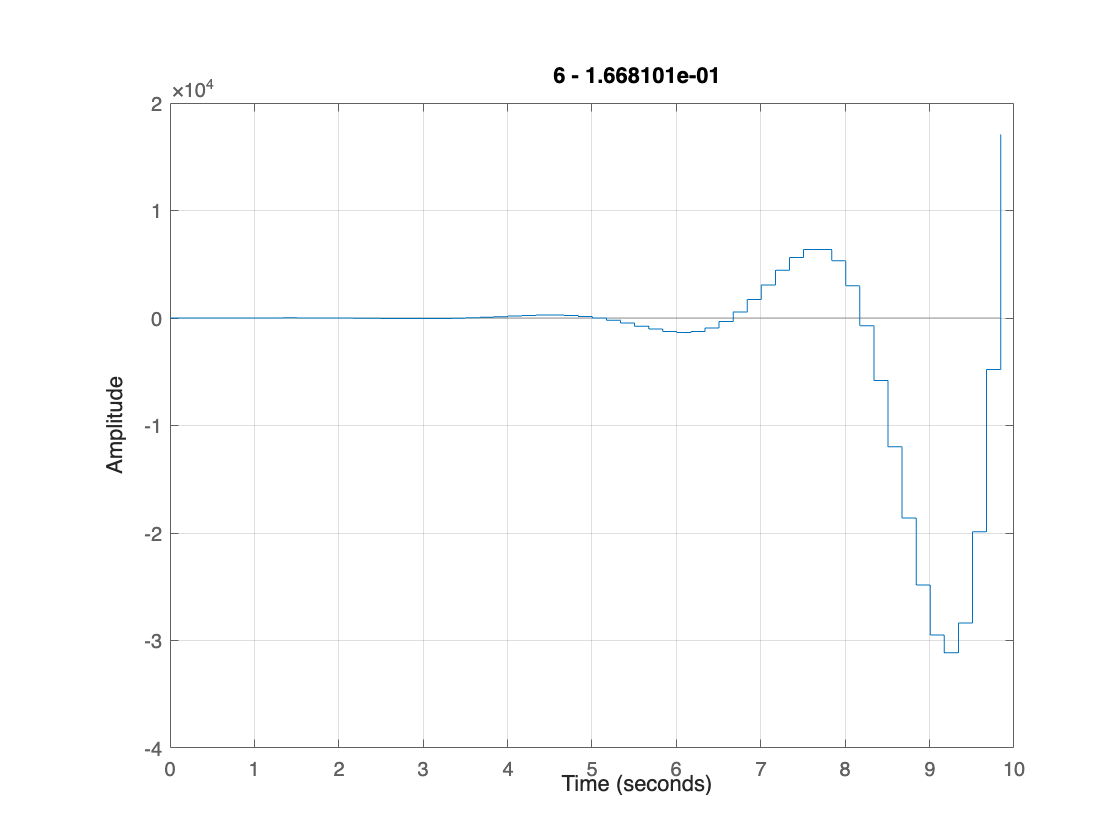

   0.9531 + 1.2735i
   0.9531 - 1.2735i



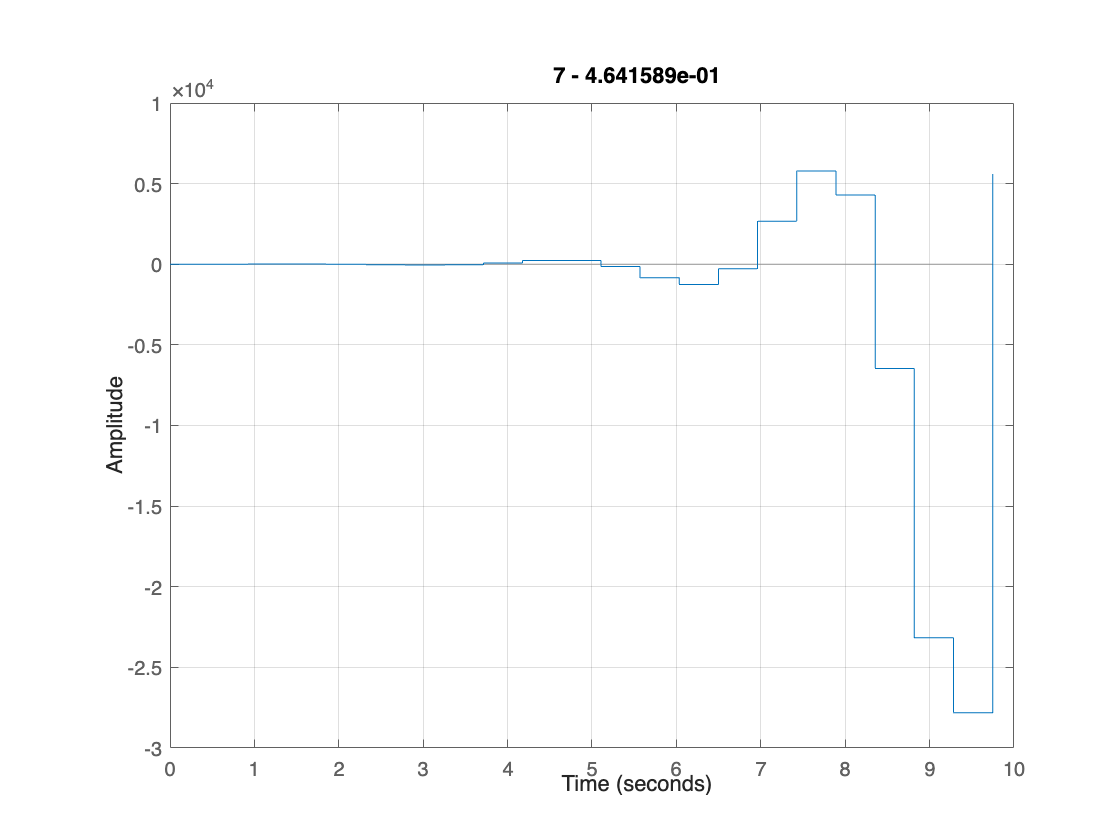

  -3.0856 + 1.9280i
  -3.0856 - 1.9280i



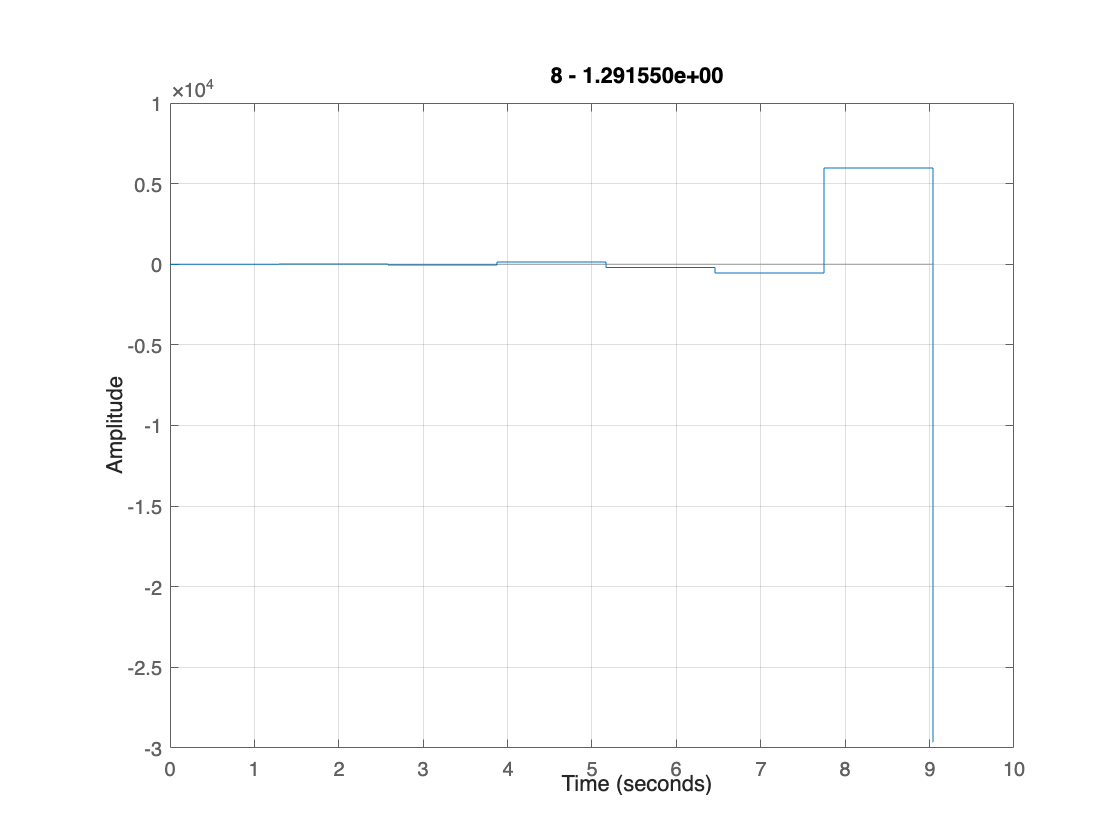

  22.4827 +28.5917i
  22.4827 -28.5917i



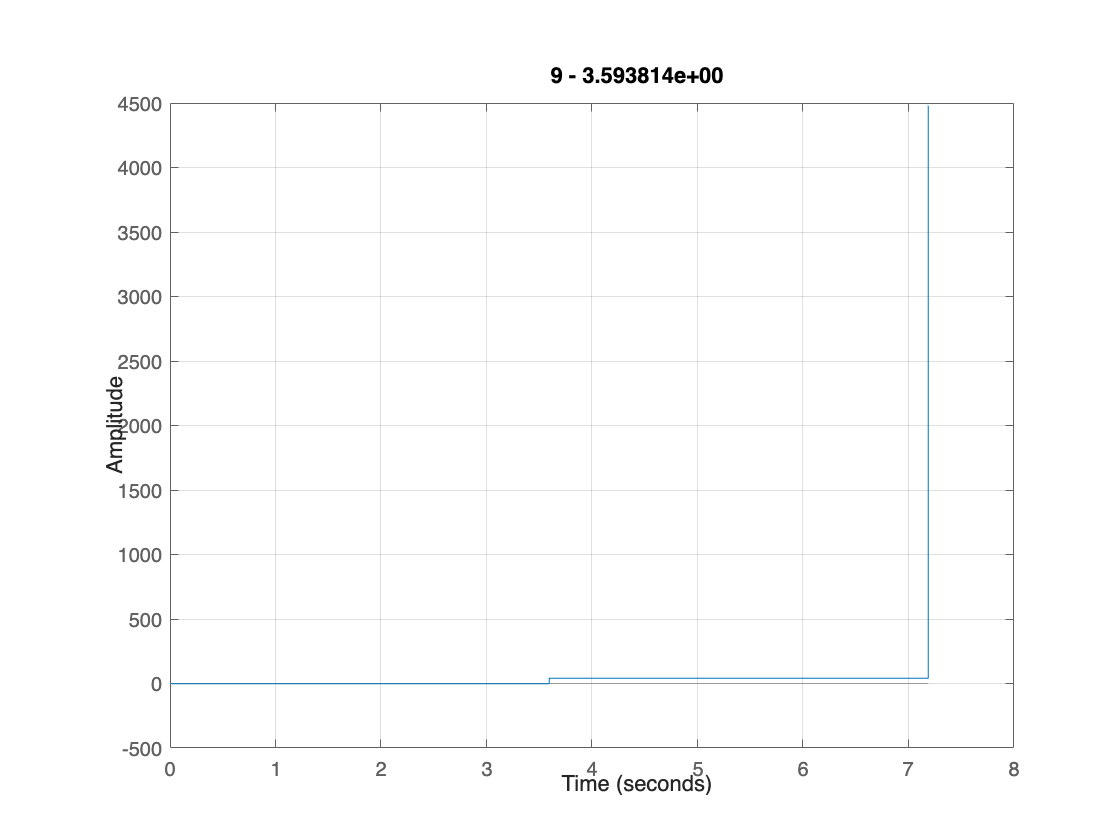

   1.0e+04 *

   0.8989 + 2.0109i
   0.8989 - 2.0109i



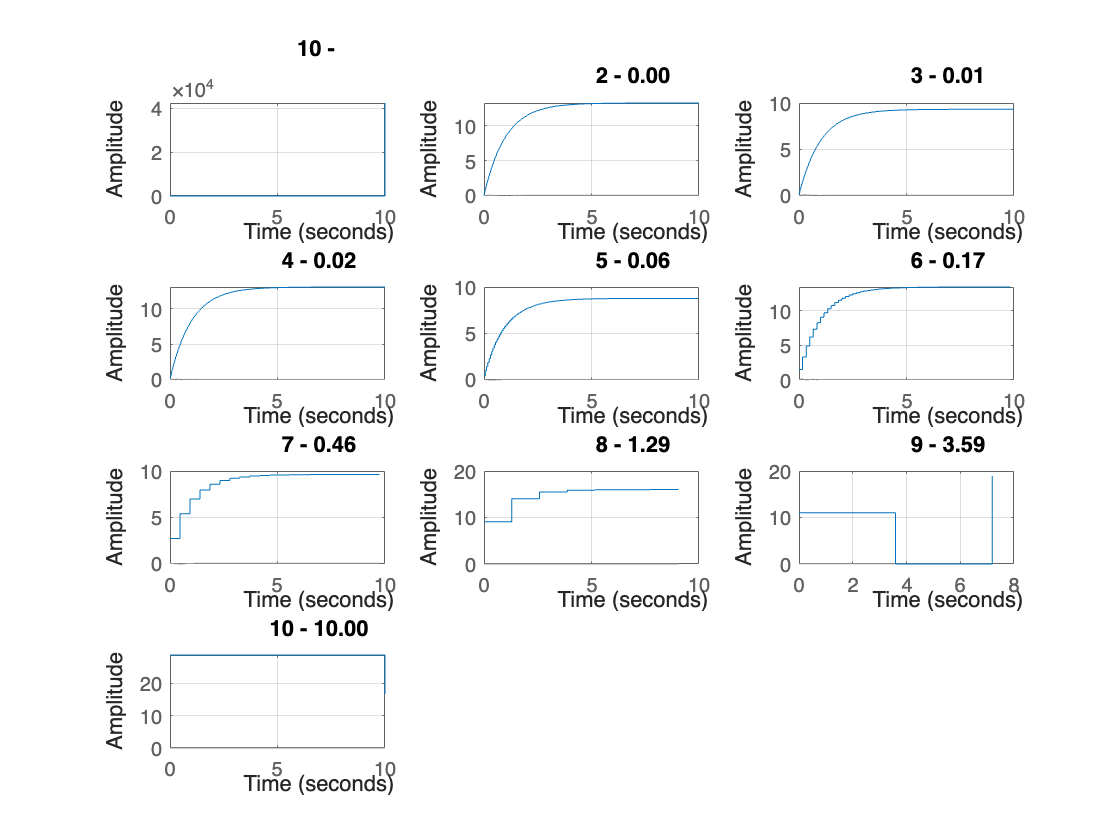

for whichOne = 1:size(Deltas, 2)
    sysD = c2d(sysC,Deltas(whichOne));
    
    % plot the eigenvalues of the discrete-time description of the given LTI system;
    
    disp(eig(sysD.A)); % we use the matrix A to compare the eigen values corresponding to the free state moevement
    
    % compare the free state movement of the continuous time system and the free state movement of each discrete time description, starting from the initial state 
    x_0 = [-2 3]';
    
    t = 0:Deltas(whichOne):10;
    U = t.*exp(-4*t) .* sin(2*pi*f*t - pi/6) .* heaviside(t);
    figure(whichOne);
    lsim(sysD, U, t, x_0);
    title(sprintf("%d - %s", whichOne, Deltas(whichOne)))
    grid on;
end

Do you find any significant difference by comparing the two cases? 